# **Tunnel Hydrogen Deflagration Experiments**

# Data Processing Procedure (DPP)

## **Objectives**

Tunnel Hydrogen deflagration time-series Analysis to determine maximum peak overpressure **∆Pmax [kPa]**.

## **Pressure Sensor Positioning**

### **Test 1-3**

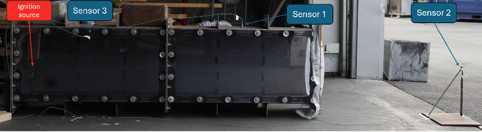

### **Test 4**

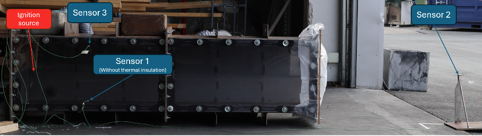

### **Test 5-7**

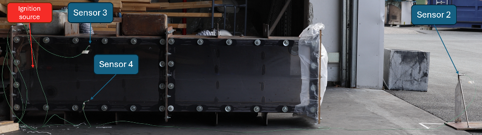

### **Test 8**

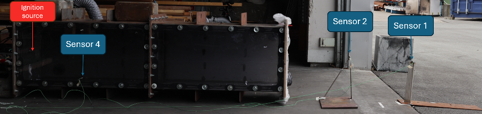

### **Test 9-11**

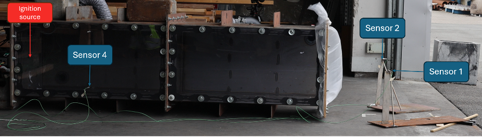

# Data Processing Procedure (DPP) Overview

**Units SI**

### 1. Data Preparation

1.1 Import Signal Data 

1.2 Plot Imported Signal Data 

1.3 Baseline/Offset Assessment 

1.4 DC-Offset-Correction

### 2. Exploratory Data Analysis (EDA)

2.1 Sample Rate Verification

2.2 Pressure Sensors Signal Verification (Data Integrity Verification)

2.3 EMI Interferance Verification 

2.4 Time Domain Analysis

        2.4.1 Baseline/Offset Assessment

        2.4.2 DC-Offset-Correction

        2.4.3 Corrected Pressure Signal Summary (DC-Offset-Corrected)

2.5 Signal Decomposition by MRA using EWT

### 3. Signal Preprocessing

3.1 Design a Low-Pass Filter

### 4. Quantity of Interest (QoI) Extraction of **∆Pmax [kPa] after Filtering**

## Matlab Startup File

This m-File code prepare the enviroment to provide access to auxilliary files and sub-folders.

clear all; clc; close all;
format short eng                              
% Plot Colors
LUCopper = [147, 86, 14]/255;LUCopper_Light = [225, 213, 199]/255;LUBlue = [17, 55, 125]/255;LUBlue_Light = [197, 204, 221]/255;
Red_Dark = [192, 0, 0]/255;Red_Light = [235, 200, 197]/255;pink = [255, 199, 206]/255;skyblue_light=[183/255 236/255 255/255];

## 1. Data Preparation 

### 1.1 Import Signal Data 

**Load Hydrogen Concentration "Raw" Signal**

**Objective:** import test-level H2 concentration targets and measured averages  for later interpretation and reporting.

**Workflow:**

- locate spreadsheet on MATLAB path

- read sheet while preserving original headers

- validate required columns

- standardize into analysis table (h2ConcTable)

- display imported table for verification

h2ConcFileName = 'Test_H2VConce.xlsx';
h2ConcFilePath = which(h2ConcFileName);
assert(~isempty(h2ConcFilePath), 'Hydrogen concentration file not found on MATLAB path: %s', h2ConcFileName);

% Keep original spreadsheet headers, then standardize to analysis-friendly names.
h2ConcOpts = detectImportOptions(h2ConcFilePath, 'FileType', 'spreadsheet');
h2ConcOpts.VariableNamingRule = 'preserve';
h2ConcRaw = readtable(h2ConcFilePath, h2ConcOpts);

assert(all(ismember(["Test #","Target Concentration [%]","avg measured conc.%"], string(h2ConcRaw.Properties.VariableNames))), ...
    'Unexpected columns in %s. Check spreadsheet headers.', h2ConcFileName);

h2TestLabel = string(strtrim(h2ConcRaw.("Test #")));
h2ConcTarget_pct = h2ConcRaw.("Target Concentration [%]");
h2ConcMeasuredAvg_pct = h2ConcRaw.("avg measured conc.%");

h2ConcTable = table(h2TestLabel, h2ConcTarget_pct, h2ConcMeasuredAvg_pct, ...
    'VariableNames', {'TestLabel','TargetConc_pct','MeasuredConcAvg_pct'});
disp(h2ConcTable);

    TestLabel    TargetConc_pct    MeasuredConcAvg_pct
    _________    ______________    ___________________

    "test1"            18                  17.5       
    "test2"            18                  17.3       
    "test3"            18                  17.4       
    "test4"            18                  17.2       
    "test5"            18                  17.4       
    "test6"            18                    17       
    "test7"            18                 17.35       
    "test8"            18                  17.4       
    "test9"            18                  17.3       
    "test10"           18                  17.4       
    "test11"           18                   NaN       



**Load Pressure "Raw" Signal**

**Objective:** import raw pressure/trigger signals for all selected tests and store them in a consistent tensor format for downstream analyses.

**Workflow:**

- load selected txt files via auxiliary loader (AuxFcn_LoadRawSignalData_000)

- validate selected files are present

- build padded tensor: (test, column, sample)

- store per-test metadata (nSamples, nChannels, dt, fs, names)

**Note: DAQ Range: 5 bar.**Details on DAQ system setting are required, to check if any hardware filters has been used.

% --- Working mode note ----------------------------------------------------
% Current analysis is channel-based (Y[0]..Y[3]).
% Sensor-to-channel mapping is pending confirmation from the experimental team.
% Keep channel labels neutral until mapping + calibration assignment are verified.

% --- Dataset selection from loaded rawData ---------------------------------
% Add/remove selected files here (loaded and analyzed together).
selectedRawDataNames = { 'Problem grounding.txt','Test 2.txt','test 3.txt','test 4.txt','test5.txt','test6.txt', ...
    'test7.txt','test8.txt','test9.txt','test10.txt','test11.txt'};
[rawData, loadedDataSummary] = AuxFcn_LoadRawSignalData_000(selectedRawDataNames);
disp(loadedDataSummary);

    FileIdx           FileName            nSamples     dt_s        fs_Hz   
    _______    _______________________    ________    _______    __________

       1       "Problem grounding.txt"    6.25e+05    4.8e-06    2.0833e+05
       2       "Test 2.txt"               6.25e+05    4.8e-06    2.0833e+05
       3       "test 3.txt"               6.25e+05    4.8e-06    2.0833e+05
       4       "test 4.txt"               6.25e+05    4.8e-06    2.0833e+05
       5       "test5.txt"                6.25e+05    4.8e-06    2.0833e+05
       6       "test6.txt"                6.25e+05    4.8e-06    2.0833e+05
       7       "test7.txt"                6.25e+05    4.8e-06    2.0833e+05
       8       "test8.txt"                6.25e+05    4.8e-06    2.0833e+05
       9       "test9.txt"                6.25e+05    4.8e-06    2.08

selectedDataIdx = find(ismember({rawData.name}, selectedRawDataNames));
missingSelected = selectedRawDataNames(~ismember(selectedRawDataNames, {rawData.name}));
assert(isempty(missingSelected), ...
    'Selected file(s) not found in loaded rawData: %s', strjoin(missingSelected, ', '));
assert(~isempty(selectedDataIdx), 'No selected datasets found. Check selectedRawDataNames.');
selectedData = rawData(selectedDataIdx);

% Build numeric 3D matrix for direct indexing: (test, channel, sample).
nTests = numel(selectedData);
nSamplesPerTest = [selectedData.nSamples];
nChannelsPerTest = [selectedData.nChannels];

% Allow unequal test lengths/channels by NaN-padding to max dimensions.
maxSamples = max(nSamplesPerTest);
maxChannels = max(nChannelsPerTest);
% testSignalTensor layout: (test, column, sample)
% column 1 = time [s], columns 2..(1+maxChannels) = channel data.
testSignalTensor = nan(nTests, 1 + maxChannels, maxSamples);
timeByTest = cell(nTests, 1);  % timeByTest{iTest}: (sample,1)

for iTest = 1:nTests
    thisSignal = selectedData(iTest).signal;      % (sample, channel)
    thisFs = selectedData(iTest).fs;              % [Hz]
    thisNSamples = size(thisSignal, 1);
    thisNChannels = size(thisSignal, 2);
    thisTime = (0:thisNSamples-1)'/thisFs;        % [s]
    testSignalTensor(iTest, 1, 1:thisNSamples) = thisTime.';                              % time
    testSignalTensor(iTest, 2:(1+thisNChannels), 1:thisNSamples) = thisSignal.';          % channels
    timeByTest{iTest} = thisTime;
end

% Optional masks/metadata for valid (non-padded) region per test.
validNSamples = nSamplesPerTest;
validNChannels = nChannelsPerTest;
testNames = string({selectedData.name});
channelNumbers = 0:(maxChannels-1);                % DAQ channel IDs: Y[0]..Y[maxChannels-1]
channelNames = "Y[" + string(channelNumbers) + "]"; % For labels/legends
dtByTest = [selectedData.dt];
fsByTest = [selectedData.fs];

### 1.2 Plot Imported Signal Data 

**Objective:** visually screen all tests/channels and highlight known regions of interest (trigger EMI and early-time channel behavior).

**Workflow:**

- loop through tests and skip those with insufficient channels

- extract first 4 channels and convert pressure channels to kPa

- plot stacked channel subplots with consistent labels/format

- add focused insets for channel-4 EMI and Test-1/channel-1 window

**Note: **using subplots for simultaneous visualization of all channels.

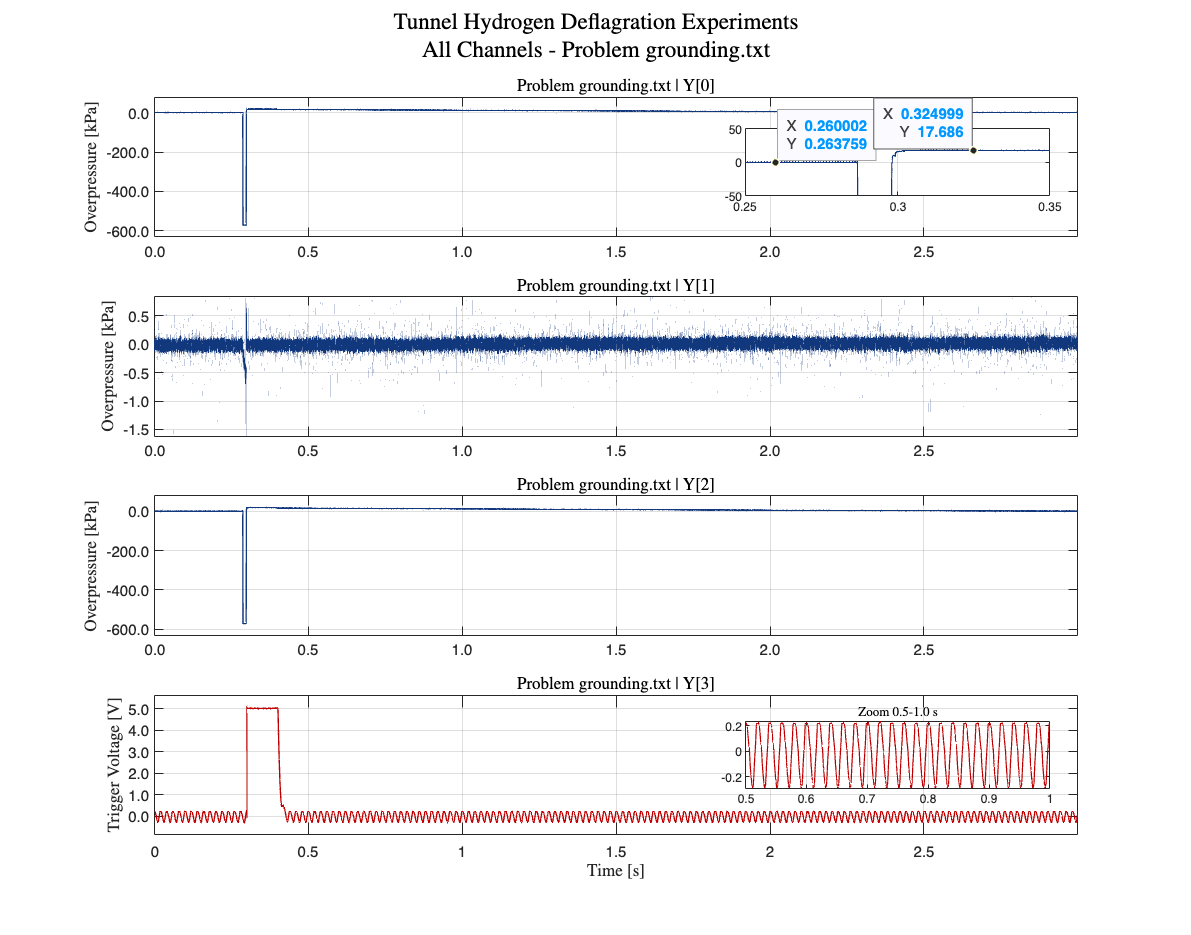

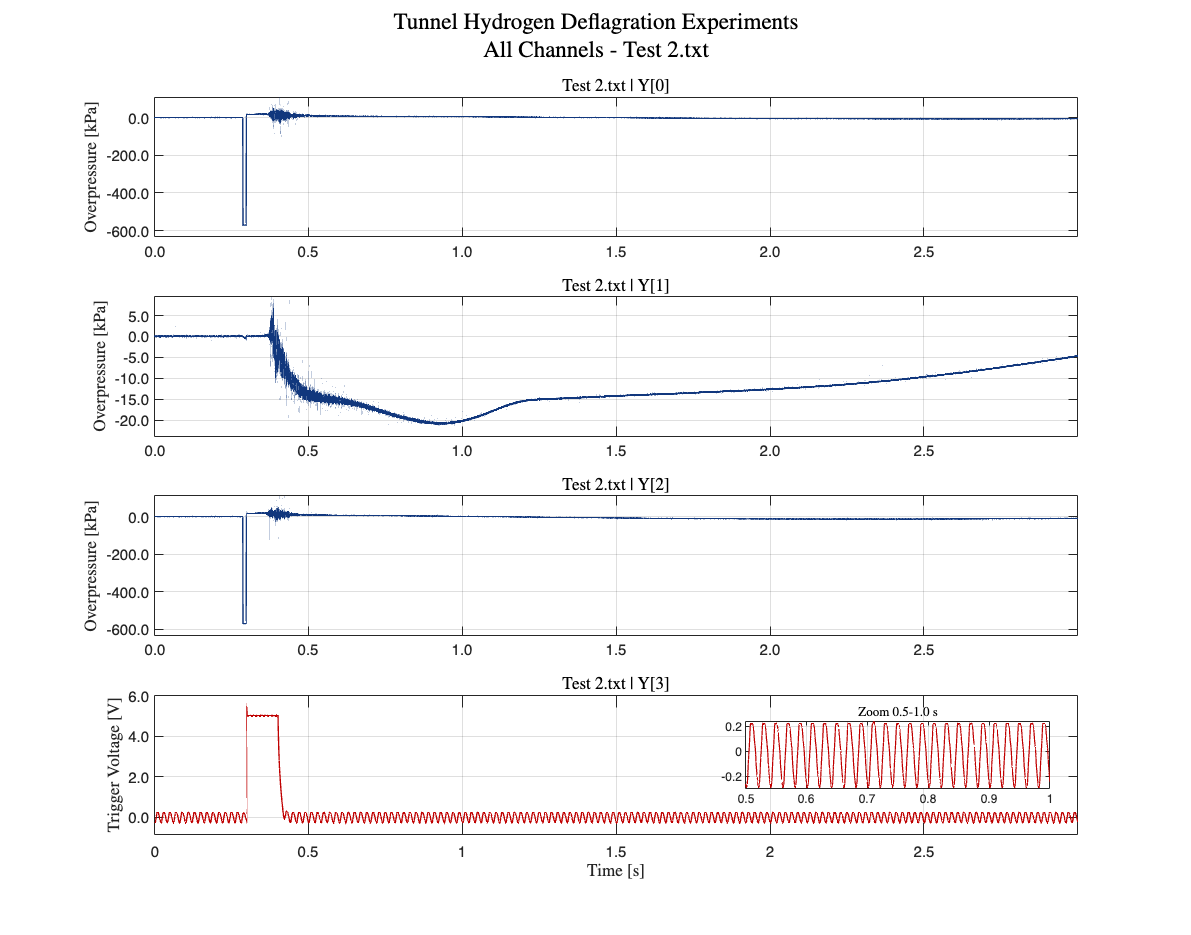

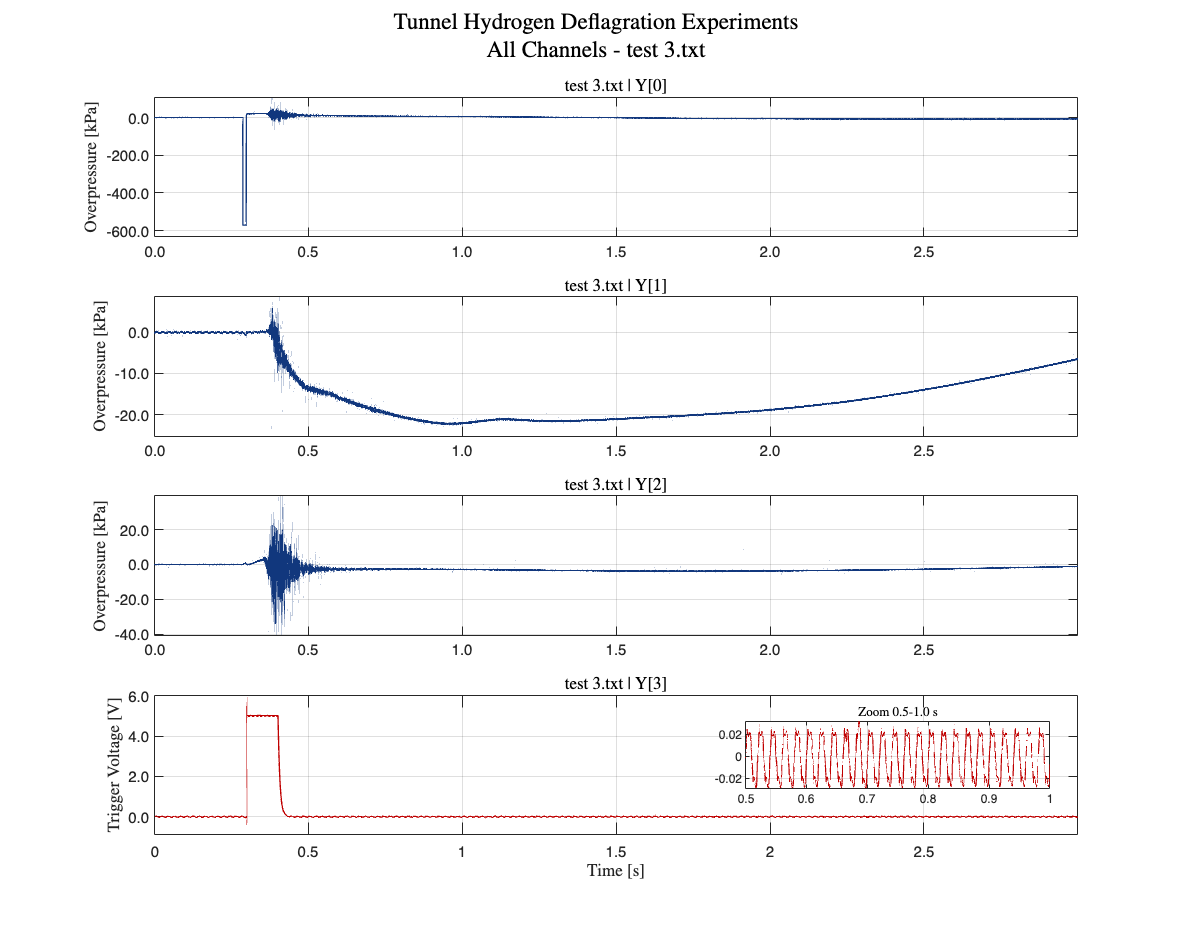

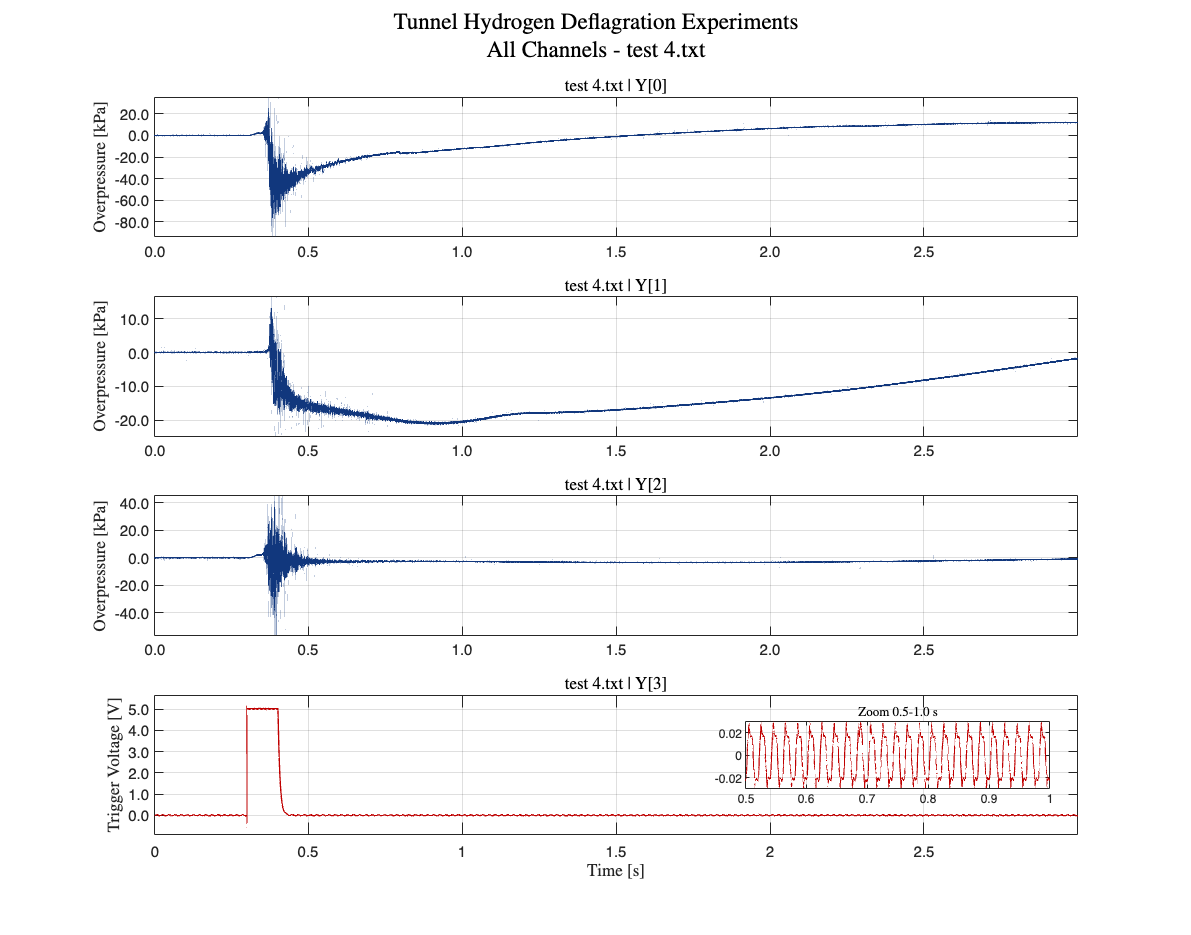

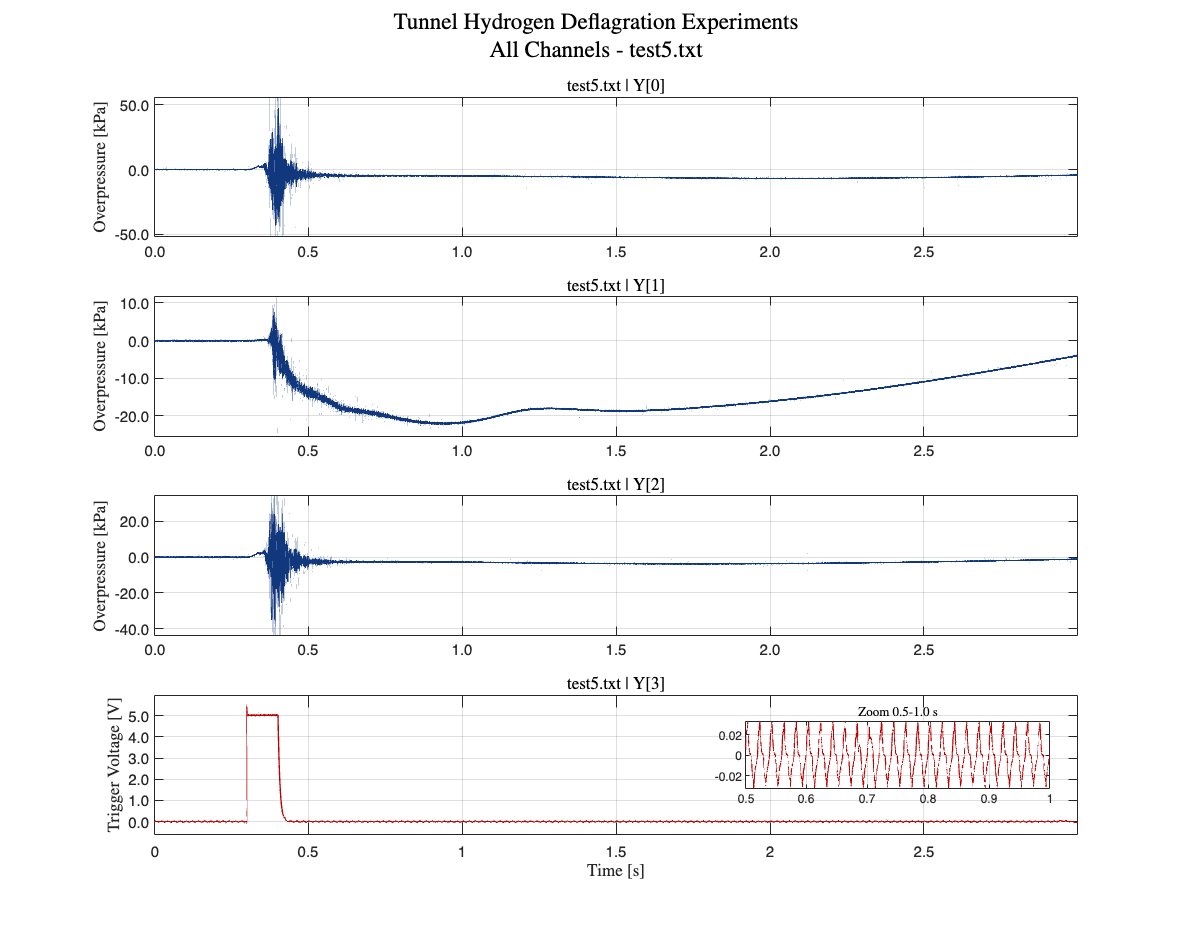

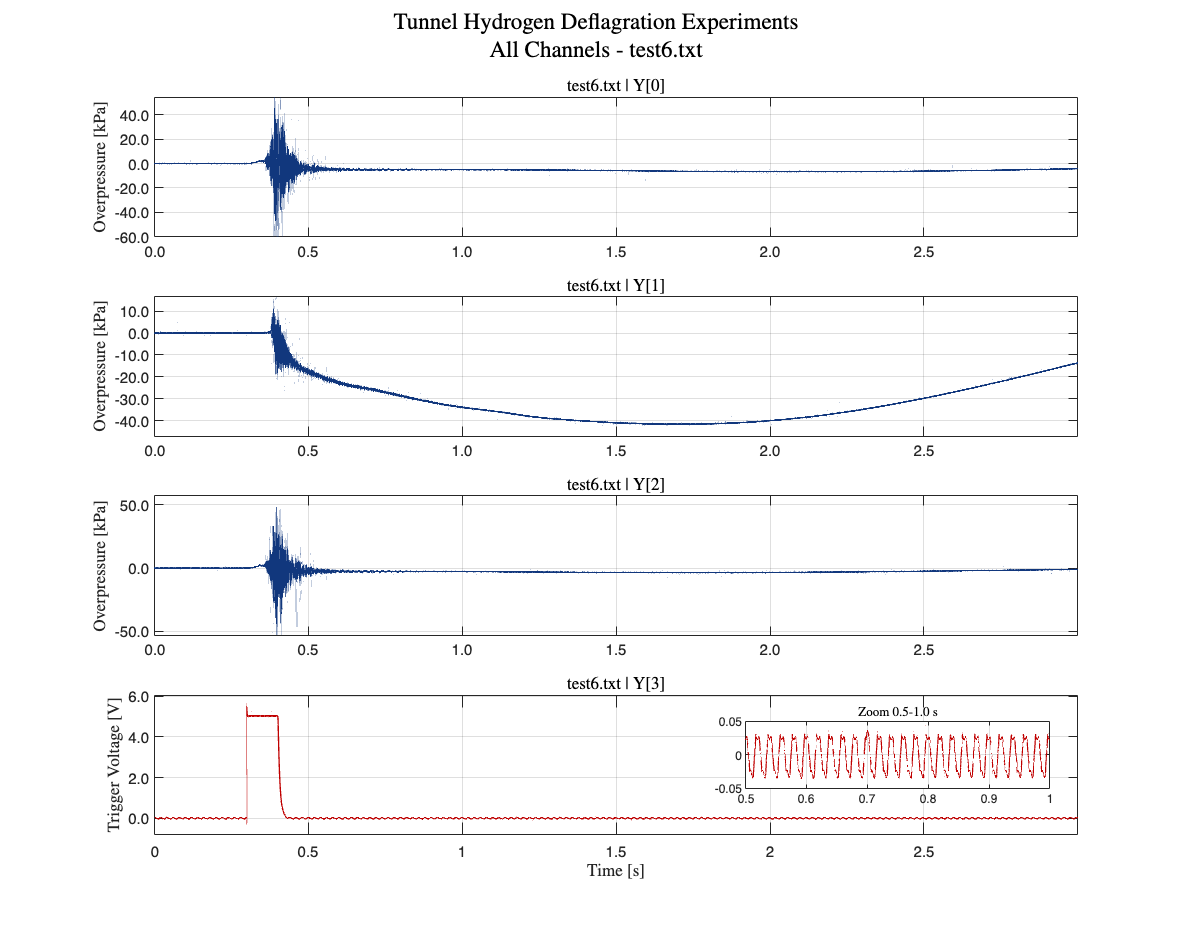

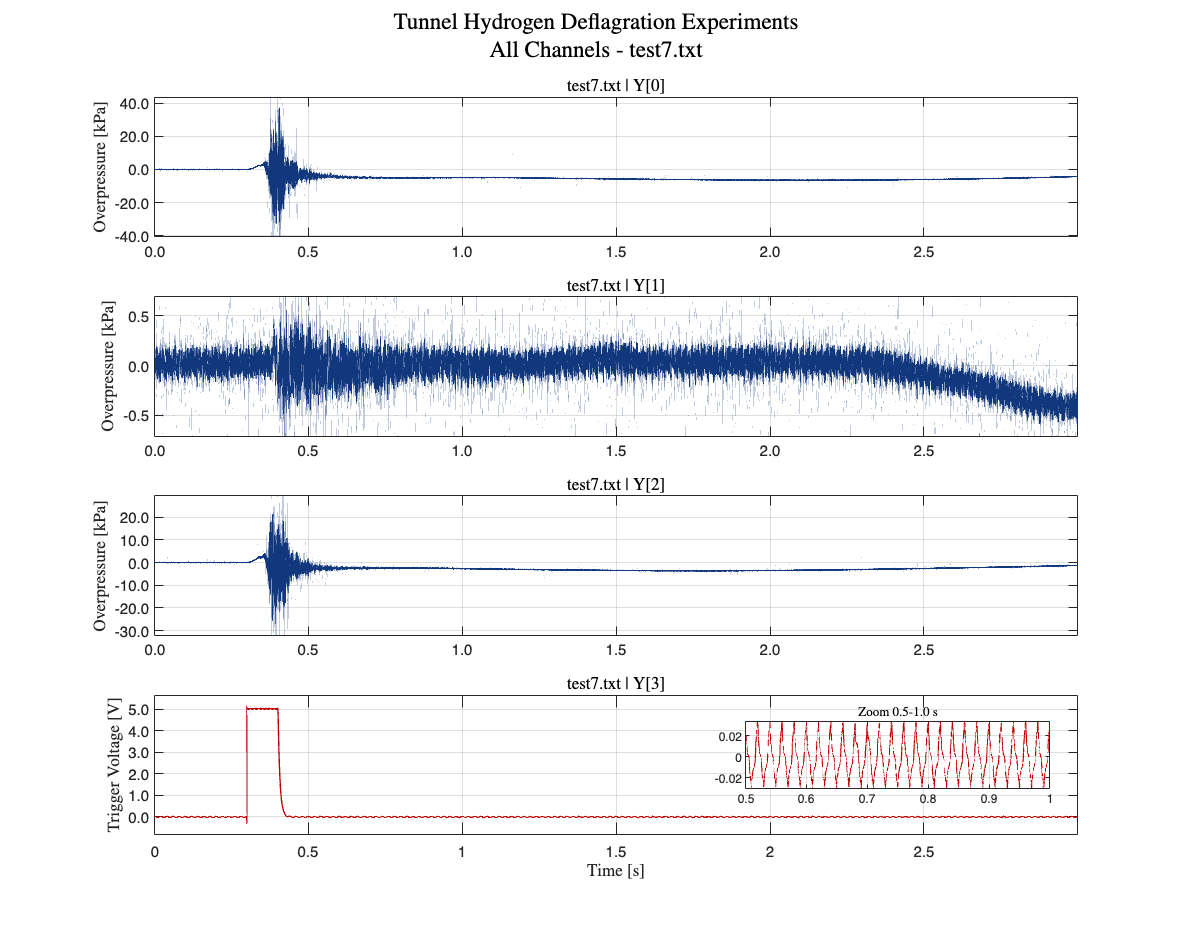

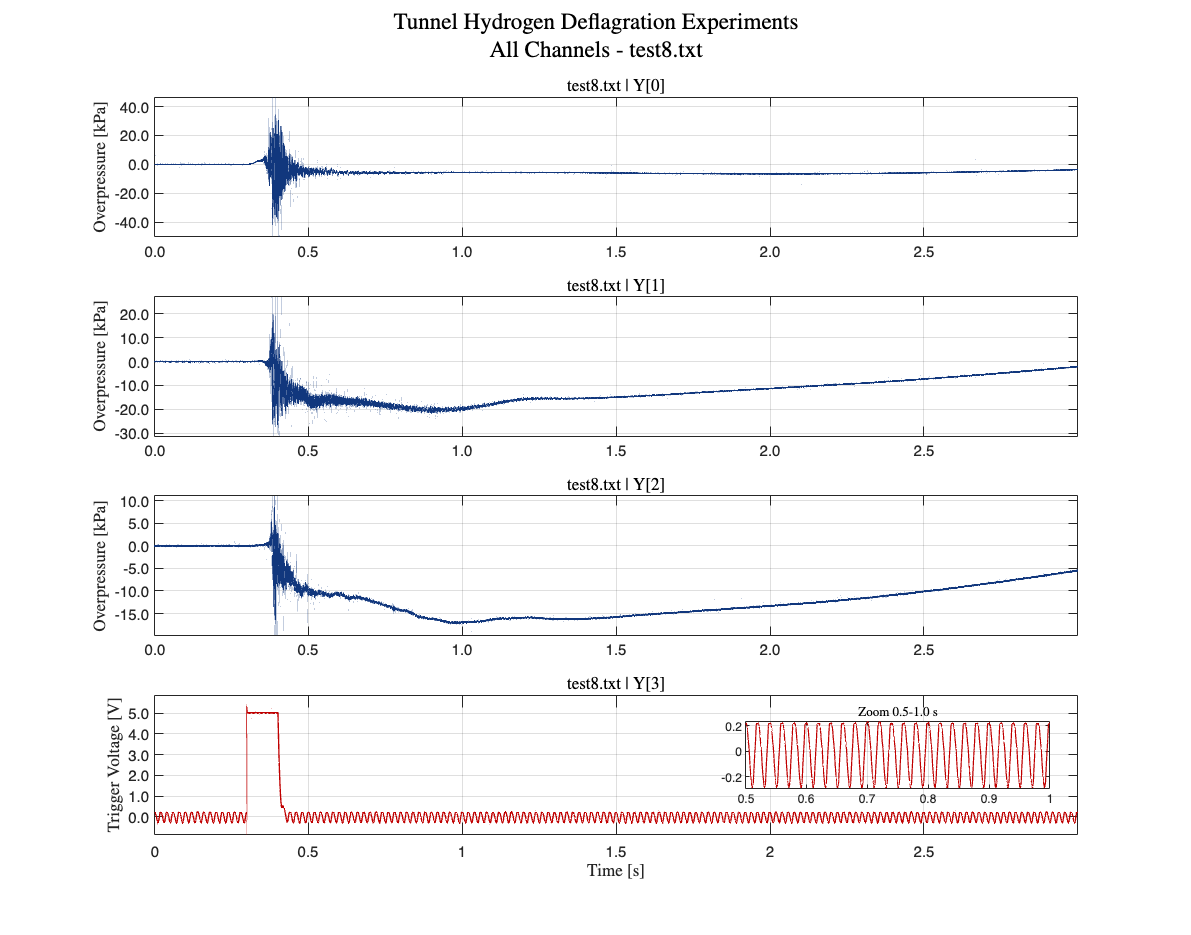

for testIdx = 1:nTests
    if validNChannels(testIdx) < 4
        warning('Skipping %s: expected at least 4 channels, found %d.', ...
            testNames(testIdx), validNChannels(testIdx));
        continue;
    end

    t_test = squeeze(testSignalTensor(testIdx, 1, 1:validNSamples(testIdx)));
    y_test = squeeze(testSignalTensor(testIdx, 2:5, 1:validNSamples(testIdx))).';  % [nSamples x 4]
    y_test(:,1:3) = y_test(:,1:3) * 100;  % Convert pressure channels to kPa

    figure;
    x0 = 10; y0 = 10; width = 28; height = 22;
    set(gcf, 'units', 'centimeters', 'position', [x0, y0, width, height]);
    sgtitle({ ...
        'Tunnel Hydrogen Deflagration Experiments'; ...
        sprintf('All Channels - %s', testNames(testIdx)) ...
        }, 'Interpreter', 'latex');

    for chIdx = 1:4
        ax = subplot(4,1,chIdx);
        if chIdx == 4
            thisColor = Red_Dark;
        else
            thisColor = LUBlue;
        end
        hLine = plot(t_test, y_test(:,chIdx), 'Color', thisColor, 'LineWidth', 0.9);
        grid on; axis tight;
        yMin = min(y_test(:,chIdx));
        yMax = max(y_test(:,chIdx));
        ySpan = yMax - yMin;
        if ySpan > 0
            yPad = 0.10 * ySpan;
        else
            yPad = 0.10 * max(abs(yMax), 1);
        end
        ylim([yMin - yPad, yMax + yPad]);
        ax.YAxis.Exponent = 0;
        ytickformat('%.1f');

        title(sprintf('%s | %s', testNames(testIdx), channelNames(chIdx)), 'Interpreter', 'latex');

        if chIdx <= 3
            ylabel('Overpressure [kPa]', 'Interpreter', 'latex');
        else
            ylabel('Trigger Voltage [V]', 'Interpreter', 'latex');
        end

        if chIdx < 4
            set(gca, 'xticklabel', []);
            xtickformat('%.1f');
        else
            xlabel('Time [s]', 'Interpreter', 'latex');
        end

        if chIdx == 4
            % Add a compact inset (0.5-1.0 s) to highlight electrical interference.
            zoomWindow = [0.5, 1.0];
            idxZoom = t_test >= zoomWindow(1) & t_test <= zoomWindow(2);
            if any(idxZoom)
                axPos = ax.Position;
                insetW = 0.33 * axPos(3);
                insetH = 0.45 * axPos(4);
                insetX = axPos(1) + 0.64 * axPos(3);
                insetY = axPos(2) + 0.30 * axPos(4);
                axInset = axes('Position', [insetX, insetY, insetW, insetH]);
                plot(axInset, t_test(idxZoom), y_test(idxZoom, chIdx), 'Color', thisColor, 'LineWidth', 0.8);
                grid(axInset, 'on');
                xlim(axInset, zoomWindow);
                title(axInset, 'Zoom 0.5-1.0 s', 'FontSize', 8, 'Interpreter', 'latex');
                set(axInset, 'FontSize', 8);
            end
        end

        if testIdx == 1 && chIdx == 1
            % Add a focused inset for Test 1, Channel 1.
            zoomWindowT1C1 = [0.25, 0.35];
            idxZoomT1C1 = t_test >= zoomWindowT1C1(1) & t_test <= zoomWindowT1C1(2);
            if any(idxZoomT1C1)
                axPos = ax.Position;
                insetW = 0.33 * axPos(3);
                insetH = 0.45 * axPos(4);
                insetX = axPos(1) + 0.64 * axPos(3);
                insetY = axPos(2) + 0.15 * axPos(4);
                axInsetT1C1 = axes('Position', [insetX, insetY, insetW, insetH]);
                hInsetLine = plot(axInsetT1C1, t_test(idxZoomT1C1), y_test(idxZoomT1C1, chIdx), ...
                    'Color', thisColor, 'LineWidth', 0.8);
                grid(axInsetT1C1, 'on');
                xlim(axInsetT1C1, zoomWindowT1C1);
                ylim(axInsetT1C1, [-50, 50]);
                title(axInsetT1C1, 'Zoom 0.275-0.30 s', 'FontSize', 8, 'Interpreter', 'latex');
                set(axInsetT1C1, 'FontSize', 8);

                % Add datatips at requested times (nearest available samples).
                tipTimes = [0.26, 0.325];
                for iTip = 1:numel(tipTimes)
                    [~, idxTip] = min(abs(t_test - tipTimes(iTip)));
                    datatip(hInsetLine, t_test(idxTip), y_test(idxTip, chIdx));
                end
            end

        end
    end
end

## 2. Exploratory Data Analysis (EDA)

### **2.1 Sample Rate Verification**

**Objective: **verify reported metadata in the generated .txt dat file and compare against DAQ system datasheet and samples time stamps.

**Workflow (Outputs to track):**

- samplingRateSummary     -> metadata vs timestamps vs datasheet

- timingUncertainty       -> mean/std/u/U95 from timestamp deltas

- samplingRateDiffSummary -> relative differences (%)


samplingRateResults = struct([]);
for iSel = 1:numel(selectedData)
    thisData = selectedData(iSel);
    [samplingRateSummary_i, timingUncertainty_i, samplingRateDiffSummary_i, samplingRateMetrics_i] = ...
        AuxFcn_SamplingRateVerification_000(thisData.tbl, thisData.dt, thisData.fs, 200e3, 2);

    samplingRateResults(iSel).name = thisData.name;
    samplingRateResults(iSel).samplingRateSummary = samplingRateSummary_i;
    samplingRateResults(iSel).timingUncertainty = timingUncertainty_i;
    samplingRateResults(iSel).samplingRateDiffSummary = samplingRateDiffSummary_i;
    samplingRateResults(iSel).samplingRateMetrics = samplingRateMetrics_i;

    fprintf('\n--- Sample-rate verification: %s ---\n', thisData.name);
    disp(samplingRateSummary_i);
    disp(timingUncertainty_i);
    disp(samplingRateDiffSummary_i);

    if abs(samplingRateMetrics_i.fsDiff_timeMean_vs_meta_pct) > 1
        warning('[%s] Timestamp mean fs and metadata fs differ by more than 1%%.', thisData.name);
    end

    if abs(samplingRateMetrics_i.fsDiff_meta_vs_datasheet_pct) > 1
        warning(['[%s] Metadata fs differs from datasheet nominal value by %.4f%% ' ...
            '(metadata: %.3f Hz, datasheet: %.3f Hz).'], ...
            thisData.name, samplingRateMetrics_i.fsDiff_meta_vs_datasheet_pct, thisData.fs, samplingRateMetrics_i.fsDataSheet);
    end
end


--- Sample-rate verification: Problem grounding.txt ---


          Source            dt_s        fs_Hz   
    ___________________    _______    __________

    "Metadata"             4.8e-06    2.0833e+05
    "Timestamps (Mean)"    4.8e-06    2.0833e+05
    "Datasheet"              5e-06         2e+05



    nIntervals     std_dt_s     u_dt_mean_s    U95_dt_mean_s    u_fs_mean_Hz    U95_fs_mean_Hz
    __________    __________    ___________    _____________    ____________    ______________

     6.25e+05     3.9999e-07    5.0596e-10      1.0119e-09         21.96            43.92     



          Comparison           dtDiff_pct     fsDiff_pct
    _______________________    ___________    __________

    "TimeMean vs Metadata"     -1.3333e-05    1.3333e-05
    "Metadata vs Datasheet"        -3.9998        4.1665
    "TimeMean vs Datasheet"        -3.9999        4.1665




--- Sample-rate verification: Test 2.txt ---


          Source            dt_s        fs_Hz   
    ___________________    _______    __________

    "Metadata"             4.8e-06    2.0833e+05
    "Timestamps (Mean)"    4.8e-06    2.0833e+05
    "Datasheet"              5e-06         2e+05



    nIntervals     std_dt_s     u_dt_mean_s    U95_dt_mean_s    u_fs_mean_Hz    U95_fs_mean_Hz
    __________    __________    ___________    _____________    ____________    ______________

     6.25e+05     3.9999e-07    5.0596e-10      1.0119e-09         21.96            43.92     



          Comparison           dtDiff_pct     fsDiff_pct
    _______________________    ___________    __________

    "TimeMean vs Metadata"     -1.3333e-05    1.3333e-05
    "Metadata vs Datasheet"        -3.9998        4.1665
    "TimeMean vs Datasheet"        -3.9999        4.1665




--- Sample-rate verification: test 3.txt ---


          Source            dt_s        fs_Hz   
    ___________________    _______    __________

    "Metadata"             4.8e-06    2.0833e+05
    "Timestamps (Mean)"    4.8e-06    2.0833e+05
    "Datasheet"              5e-06         2e+05



    nIntervals     std_dt_s     u_dt_mean_s    U95_dt_mean_s    u_fs_mean_Hz    U95_fs_mean_Hz
    __________    __________    ___________    _____________    ____________    ______________

     6.25e+05     3.9999e-07    5.0596e-10      1.0119e-09         21.96            43.92     



          Comparison           dtDiff_pct     fsDiff_pct
    _______________________    ___________    __________

    "TimeMean vs Metadata"     -1.3333e-05    1.3333e-05
    "Metadata vs Datasheet"        -3.9998        4.1665
    "TimeMean vs Datasheet"        -3.9999        4.1665




--- Sample-rate verification: test 4.txt ---


          Source            dt_s        fs_Hz   
    ___________________    _______    __________

    "Metadata"             4.8e-06    2.0833e+05
    "Timestamps (Mean)"    4.8e-06    2.0833e+05
    "Datasheet"              5e-06         2e+05



    nIntervals     std_dt_s     u_dt_mean_s    U95_dt_mean_s    u_fs_mean_Hz    U95_fs_mean_Hz
    __________    __________    ___________    _____________    ____________    ______________

     6.25e+05     3.9999e-07    5.0596e-10      1.0119e-09         21.96            43.92     



          Comparison           dtDiff_pct     fsDiff_pct
    _______________________    ___________    __________

    "TimeMean vs Metadata"     -1.3333e-05    1.3333e-05
    "Metadata vs Datasheet"        -3.9998        4.1665
    "TimeMean vs Datasheet"        -3.9999        4.1665




--- Sample-rate verification: test5.txt ---


          Source            dt_s        fs_Hz   
    ___________________    _______    __________

    "Metadata"             4.8e-06    2.0833e+05
    "Timestamps (Mean)"    4.8e-06    2.0833e+05
    "Datasheet"              5e-06         2e+05



    nIntervals     std_dt_s     u_dt_mean_s    U95_dt_mean_s    u_fs_mean_Hz    U95_fs_mean_Hz
    __________    __________    ___________    _____________    ____________    ______________

     6.25e+05     3.9999e-07    5.0596e-10      1.0119e-09         21.96            43.92     



          Comparison           dtDiff_pct     fsDiff_pct
    _______________________    ___________    __________

    "TimeMean vs Metadata"     -1.3333e-05    1.3333e-05
    "Metadata vs Datasheet"        -3.9998        4.1665
    "TimeMean vs Datasheet"        -3.9999        4.1665




--- Sample-rate verification: test6.txt ---


          Source            dt_s        fs_Hz   
    ___________________    _______    __________

    "Metadata"             4.8e-06    2.0833e+05
    "Timestamps (Mean)"    4.8e-06    2.0833e+05
    "Datasheet"              5e-06         2e+05



    nIntervals     std_dt_s     u_dt_mean_s    U95_dt_mean_s    u_fs_mean_Hz    U95_fs_mean_Hz
    __________    __________    ___________    _____________    ____________    ______________

     6.25e+05     3.9999e-07    5.0596e-10      1.0119e-09         21.96            43.92     



          Comparison           dtDiff_pct     fsDiff_pct
    _______________________    ___________    __________

    "TimeMean vs Metadata"     -1.3333e-05    1.3333e-05
    "Metadata vs Datasheet"        -3.9998        4.1665
    "TimeMean vs Datasheet"        -3.9999        4.1665




--- Sample-rate verification: test7.txt ---


          Source            dt_s        fs_Hz   
    ___________________    _______    __________

    "Metadata"             4.8e-06    2.0833e+05
    "Timestamps (Mean)"    4.8e-06    2.0833e+05
    "Datasheet"              5e-06         2e+05



    nIntervals     std_dt_s     u_dt_mean_s    U95_dt_mean_s    u_fs_mean_Hz    U95_fs_mean_Hz
    __________    __________    ___________    _____________    ____________    ______________

     6.25e+05     3.9999e-07    5.0596e-10      1.0119e-09         21.96            43.92     



          Comparison           dtDiff_pct     fsDiff_pct
    _______________________    ___________    __________

    "TimeMean vs Metadata"     -1.3333e-05    1.3333e-05
    "Metadata vs Datasheet"        -3.9998        4.1665
    "TimeMean vs Datasheet"        -3.9999        4.1665




--- Sample-rate verification: test8.txt ---


          Source            dt_s        fs_Hz   
    ___________________    _______    __________

    "Metadata"             4.8e-06    2.0833e+05
    "Timestamps (Mean)"    4.8e-06    2.0833e+05
    "Datasheet"              5e-06         2e+05



    nIntervals     std_dt_s     u_dt_mean_s    U95_dt_mean_s    u_fs_mean_Hz    U95_fs_mean_Hz
    __________    __________    ___________    _____________    ____________    ______________

     6.25e+05     3.9999e-07    5.0596e-10      1.0119e-09         21.96            43.92     



          Comparison           dtDiff_pct     fsDiff_pct
    _______________________    ___________    __________

    "TimeMean vs Metadata"     -1.3333e-05    1.3333e-05
    "Metadata vs Datasheet"        -3.9998        4.1665
    "TimeMean vs Datasheet"        -3.9999        4.1665




--- Sample-rate verification: test9.txt ---


          Source            dt_s        fs_Hz   
    ___________________    _______    __________

    "Metadata"             4.8e-06    2.0833e+05
    "Timestamps (Mean)"    4.8e-06    2.0833e+05
    "Datasheet"              5e-06         2e+05



    nIntervals     std_dt_s     u_dt_mean_s    U95_dt_mean_s    u_fs_mean_Hz    U95_fs_mean_Hz
    __________    __________    ___________    _____________    ____________    ______________

     6.25e+05     3.9999e-07    5.0596e-10      1.0119e-09         21.96            43.92     



          Comparison           dtDiff_pct     fsDiff_pct
    _______________________    ___________    __________

    "TimeMean vs Metadata"     -1.3333e-05    1.3333e-05
    "Metadata vs Datasheet"        -3.9998        4.1665
    "TimeMean vs Datasheet"        -3.9999        4.1665




--- Sample-rate verification: test10.txt ---


          Source            dt_s        fs_Hz   
    ___________________    _______    __________

    "Metadata"             4.8e-06    2.0833e+05
    "Timestamps (Mean)"    4.8e-06    2.0833e+05
    "Datasheet"              5e-06         2e+05



    nIntervals     std_dt_s     u_dt_mean_s    U95_dt_mean_s    u_fs_mean_Hz    U95_fs_mean_Hz
    __________    __________    ___________    _____________    ____________    ______________

     6.25e+05     3.9999e-07    5.0596e-10      1.0119e-09         21.96            43.92     



          Comparison           dtDiff_pct     fsDiff_pct
    _______________________    ___________    __________

    "TimeMean vs Metadata"     -1.3333e-05    1.3333e-05
    "Metadata vs Datasheet"        -3.9998        4.1665
    "TimeMean vs Datasheet"        -3.9999        4.1665




--- Sample-rate verification: test11.txt ---


          Source            dt_s        fs_Hz   
    ___________________    _______    __________

    "Metadata"             4.8e-06    2.0833e+05
    "Timestamps (Mean)"    4.8e-06    2.0833e+05
    "Datasheet"              5e-06         2e+05



    nIntervals     std_dt_s     u_dt_mean_s    U95_dt_mean_s    u_fs_mean_Hz    U95_fs_mean_Hz
    __________    __________    ___________    _____________    ____________    ______________

     6.25e+05     3.9999e-07    5.0596e-10      1.0119e-09         21.96            43.92     



          Comparison           dtDiff_pct     fsDiff_pct
    _______________________    ___________    __________

    "TimeMean vs Metadata"     -1.3333e-05    1.3333e-05
    "Metadata vs Datasheet"        -3.9998        4.1665
    "TimeMean vs Datasheet"        -3.9999        4.1665



### **2.2 Pressure Sensors Signal Verification (**Data Integrity Verification)

**Objective: **verify the impact of the ignition mechanism (Channel 4 (Y)) on pressure sensors. Time when ignition tigger

**Workflow:**

- extract Test 1 pressure channel (Y[0]) and trigger channel (Y[3])

- convert pressure to kPa

- plot both channels with dual y-axes for time alignment check

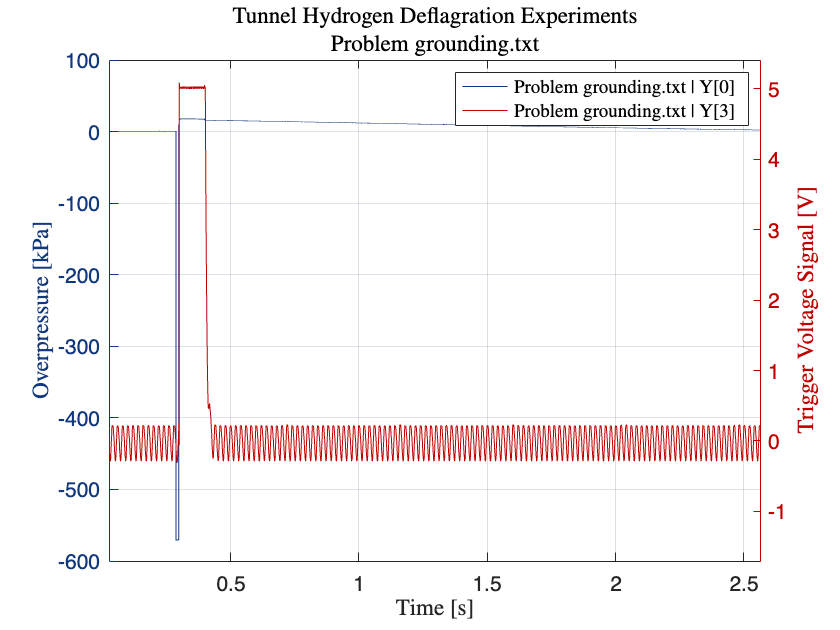

testIdx = 1; 
chIdx = 1; % chIdx=1 -> Y[0]
t_1_1 = squeeze(testSignalTensor(testIdx,1,1:validNSamples(testIdx)));  
y_1_1 = squeeze(testSignalTensor(testIdx,1+chIdx,1:validNSamples(testIdx))) * 100; % [kPa]
label_1_1 = sprintf('%s | %s', testNames(testIdx), channelNames(chIdx));
testIdx = 1; 
chIdx = 4;  % chIdx=4 -> Y[3]
t_1_4 = squeeze(testSignalTensor(testIdx,1,1:validNSamples(testIdx)));
y_1_4 = squeeze(testSignalTensor(testIdx,1+chIdx,1:validNSamples(testIdx)));
label_1_4 = sprintf('%s | %s', testNames(testIdx), channelNames(chIdx));

figure; 
colororder([LUBlue; Red_Dark])
yyaxis left
plot(t_1_1, y_1_1); 
ylabel('Overpressure [kPa]','Interpreter','latex')
hold on;
yyaxis right
plot(t_1_4, y_1_4);
ylabel('Trigger Voltage Signal [V]','Interpreter','latex')
legend(label_1_1, label_1_4,'Location', 'northeast','Interpreter','latex');
xlabel('Time [s]','Interpreter','latex')
title({'Tunnel Hydrogen Deflagration Experiments',testNames(testIdx)},'Interpreter','latex')
% sgtitle({ ...
%     'Tunnel Hydrogen Deflagration Experiments'; ...
%     sprintf('All Channels - %s', testNames(testIdx)) ...
%     }, 'Interpreter', 'latex');

Font_Size=14;
set(gca, 'FontName', "Helvetica") ;
box on                                       % draw a box around plot
set(gcf,'color','w');                        % set background to white
set(gca,'Fontsize', Font_Size);                      % set the fontsize
grid on

### **2.3 EMI Interferance Verification **

(Trigger Noise Frequency Verification)

**Objective: **verify whether trigger-channel oscillation in Test 1 is consistent with 50 Hz power-line EMI (Europe).

**Workflow:**

- isolate the suspect interval (0.5-1.0 s) from Test 1, Channel 4

- remove DC offset and apply Hann window (lower spectral leakage)

- compute the single-sided FFT amplitude spectrum

- quantify peaks near 50 Hz and in a broader 40-80 Hz band

- plot time-domain segment + spectrum with 50/100/150 Hz references

emiTestIdx = 1;          % Test used for EMI check
emiChIdx = 4;            % Channel 4 -> Y[3] trigger signal
emiWindow = [0.5, 1.0];  % Analysis time window [s]

assert(emiTestIdx >= 1 && emiTestIdx <= nTests, 'emiTestIdx out of range.');
assert(validNChannels(emiTestIdx) >= emiChIdx, ...
    'Selected test does not contain channel %d.', emiChIdx);

[t_emi, y_emi, fs_emi] = AuxFcn_GetWindowedSignal_000( ...
    testSignalTensor, validNSamples, fsByTest, emiTestIdx, emiChIdx, emiWindow, false);%convertPressureToKPa false signal is volts
N_emi = numel(y_emi);

% Remove mean to suppress DC, then taper edges before FFT.
y_emi_detr = y_emi - mean(y_emi, 'omitnan');
if exist('hann', 'file')
    w_emi = hann(N_emi);
else
    w_emi = hanning(N_emi);
end
y_emi_win = y_emi_detr .* w_emi;

% FFT to one-sided amplitude spectrum (resolution = fs_emi/N_emi).
Y_emi = fft(y_emi_win);
P2_emi = abs(Y_emi / N_emi);
P1_emi = P2_emi(1:floor(N_emi/2)+1);
if numel(P1_emi) > 2
    P1_emi(2:end-1) = 2 * P1_emi(2:end-1);
end
f_emi = fs_emi * (0:floor(N_emi/2)) / N_emi;

% Peak search around nominal mains frequency.
searchBW = 2;  % +/- Hz around 50 Hz
idx50 = f_emi >= (50 - searchBW) & f_emi <= (50 + searchBW);

f50_peak = NaN; A50_peak = NaN;
if any(idx50)
    [A50_peak, i50] = max(P1_emi(idx50));
    f50_vec = f_emi(idx50);
    f50_peak = f50_vec(i50);
end

% Also identify dominant component in a broader EMI band.
emiBand = [40, 80];
idxBand = f_emi >= emiBand(1) & f_emi <= emiBand(2);
f_dom = NaN; A_dom = NaN;
if any(idxBand)
    [A_dom, iDom] = max(P1_emi(idxBand));
    fBand = f_emi(idxBand);
    f_dom = fBand(iDom);
end

fprintf('\n--- EMI verification (Test %d, Channel %d, %.3f-%.3f s) ---\n', ...
    emiTestIdx, emiChIdx, emiWindow(1), emiWindow(2));


--- EMI verification (Test 1, Channel 4, 0.500-1.000 s) ---


fprintf('Peak near 50 Hz: f = %.3f Hz, A = %.5g\n', f50_peak, A50_peak);

Peak near 50 Hz: f = 50.000 Hz, A = 0.12701


fprintf('Dominant peak in %.0f-%.0f Hz band: f = %.3f Hz, A = %.5g\n', ...
    emiBand(1), emiBand(2), f_dom, A_dom);

Dominant peak in 40-80 Hz band: f = 50.000 Hz, A = 0.12701



% Compact summary table + interpretation for reporting.
idx100 = f_emi >= (100 - searchBW) & f_emi <= (100 + searchBW);
idx150 = f_emi >= (150 - searchBW) & f_emi <= (150 + searchBW);
f100_peak = NaN; A100_peak = NaN;
f150_peak = NaN; A150_peak = NaN;
if any(idx100)
    [A100_peak, i100] = max(P1_emi(idx100));
    f100_vec = f_emi(idx100);
    f100_peak = f100_vec(i100);
end
if any(idx150)
    [A150_peak, i150] = max(P1_emi(idx150));
    f150_vec = f_emi(idx150);
    f150_peak = f150_vec(i150);
end

idxBandNo50 = idxBand & ~(f_emi >= (50 - searchBW) & f_emi <= (50 + searchBW));
A_band_no50 = P1_emi(idxBandNo50);
if isempty(A_band_no50)
    A_band_no50_med = NaN;
else
    A_band_no50_med = median(A_band_no50, 'omitnan');
end
prominence50 = A50_peak / A_band_no50_med;

emiSummaryTable = table( ...
    emiTestIdx, emiChIdx, emiWindow(1), emiWindow(2), ...
    f50_peak, A50_peak, f100_peak, A100_peak, f150_peak, A150_peak, ...
    f_dom, A_dom, prominence50, ...
    'VariableNames', { ...
    'TestIdx','ChannelIdx','WindowStart_s','WindowEnd_s', ...
    'Peak50_Hz','Amp50_V','Peak100_Hz','Amp100_V','Peak150_Hz','Amp150_V', ...
    'Dominant40to80_Hz','Dominant40to80Amp_V','Prominence50_vsBandMedian'});
disp(emiSummaryTable);

    TestIdx    ChannelIdx    WindowStart_s    WindowEnd_s    Peak50_Hz    Amp50_V    Peak100_Hz    Amp100_V    Peak150_Hz    Amp150_V     Dominant40to80_Hz    Dominant40to80Amp_V    Prominence50_vsBandMedian
    _______    __________    _____________    ___________    _________    _______    __________    ________    __________    _________    _________________    ___________________    _________________________

       1           4              0.5              1            50        0.12701       100        0.018048       150        0.0028628       


if ~isnan(f_dom) && abs(f_dom - 50) <= 1.5 && ~isnan(prominence50) && prominence50 >= 10
    emiInterpretation = sprintf(['EMI conclusion: Strong evidence of 50 Hz mains interference ' ...
        '(dominant %.2f Hz; prominence %.1fx above 40-80 Hz median excluding 50 Hz).'], ...
        f_dom, prominence50);
elseif ~isnan(f_dom) && abs(f_dom - 50) <= 3
    emiInterpretation = sprintf(['EMI conclusion: Likely 50 Hz mains interference ' ...
        '(dominant %.2f Hz), but with weaker separation from background.'], f_dom);
else
    emiInterpretation = sprintf(['EMI conclusion: Inconclusive for 50 Hz dominance ' ...
        '(dominant %.2f Hz in 40-80 Hz band).'], f_dom);
end
fprintf('%s\n', emiInterpretation);

EMI conclusion: Strong evidence of 50 Hz mains interference (dominant 50.00 Hz; prominence 596.9x above 40-80 Hz median excluding 50 Hz).


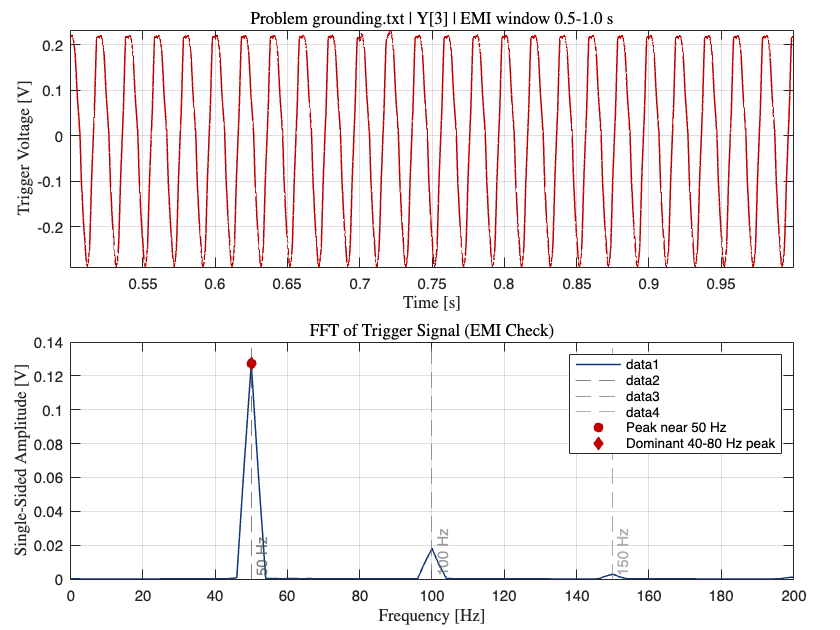


% Visualization:
% top panel   -> trigger oscillation in 0.5-1.0 s window
% bottom panel-> FFT magnitude with 50 Hz and harmonic guides
figure;
tiledlayout(2,1, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile;
plot(t_emi, y_emi, 'Color', Red_Dark, 'LineWidth', 1.0);
grid on; axis tight;
xlabel('Time [s]', 'Interpreter', 'latex');
ylabel('Trigger Voltage [V]', 'Interpreter', 'latex');
title(sprintf('%s | %s | EMI window %.1f-%.1f s', ...
    testNames(emiTestIdx), channelNames(emiChIdx), emiWindow(1), emiWindow(2)), ...
    'Interpreter', 'latex');

nexttile;
plot(f_emi, P1_emi, 'Color', LUBlue, 'LineWidth', 1.0); hold on;
xline(50, '--', '50 Hz', 'Color', [0.30 0.30 0.30], 'LabelVerticalAlignment', 'bottom');
xline(100, '--', '100 Hz', 'Color', [0.45 0.45 0.45], 'LabelVerticalAlignment', 'bottom');
xline(150, '--', '150 Hz', 'Color', [0.55 0.55 0.55], 'LabelVerticalAlignment', 'bottom');
if ~isnan(f50_peak)
    plot(f50_peak, A50_peak, 'o', 'Color', Red_Dark, ...
        'MarkerFaceColor', Red_Dark, 'DisplayName', 'Peak near 50 Hz');
end
if ~isnan(f_dom)
    plot(f_dom, A_dom, 'd', 'Color', Red_Dark, ...
        'MarkerFaceColor', Red_Dark, 'DisplayName', 'Dominant 40-80 Hz peak');
end
grid on;
xlim([0, min(200, fs_emi/2)]);
xlabel('Frequency [Hz]', 'Interpreter', 'latex');
ylabel('Single-Sided Amplitude [V]', 'Interpreter', 'latex');
title('FFT of Trigger Signal (EMI Check)', 'Interpreter', 'latex');
legend('Location', 'northeast');

### 2.4 Time Domain Analysis

#### **2.4.1 Baseline/Offset Assessment **

**Objective: **Identify any baseline offset and decide on necessary baseline correction.

**Workflow:**

- select pre-event sample window

- compute per-channel baseline statistics

- decide whether offset removal is required

**Note: **Offset correction based on the** first 100 samples.**

#### **2.4.2 DC-Offset-Correction**

**Objective: **Pressure reading corrected (offset/baseline removed)

**Workflow:**

- estimate baseline from pre-event segment

- subtract baseline from pressure channels

- verify corrected traces preserve event dynamics

#### 2.4.3 Corrected Pressure Signal Summary (DC-Offset-Corrected)

**Objective:** quantify key time-domain metrics from corrected pressure signals (peak overpressure, minimum pressure, timing, impulse, and energy).

**Workflow:**

- use DC-offset-corrected pressure signals

- compute pMax/pMin and corresponding occurrence times

- compute impulse and cumulative impulse check

- compute total signal energy

- compile summary table for cross-test comparison

**Compute Pressure max, and min across each test**

% [pMax, idx] = max(dataP, [], 1); % [kPa]
% pMaxT = t(idx); % [ms]
% [pMin, idx] = min(dataP, [], 1); % [kPa]
% pMinT = t(idx); % [ms]

**Compute Impulse and Signal Energy [kPa.ms]**

% impulseP = trapz(t, dataP)';

**Impulse Check by Cumulative**

% impulseP_check = cumtrapz(t, dataP)';
% Icheck = (impulseP_check(:,end)./impulseP) * 100;
% figure;
% plot(t,impulseP_check(12,:));  % Should show a smooth increasing function
% hold off

**Compute Signal Energy [kPa^2]**

% energySignal = sum(abs(dataP).^2)';  % Total energy

**Table Summary**

% dataSummary = table(testNum',round(dataRMH',2), round(pMax',1),pMaxT, round(pMin',1),pMinT,round(impulseP,1),round(energySignal,1), ...
%     'VariableNames', {'Test Number','Released Mass of Hydrogen [g]', 'Pmax. [kPa]','Pmax.Time[s]', 'Pmin. [kPa]','Pmin.Time[s]', 'Impulse [kPa.s]','Signal Energy [kPa^2]'});
% disp(dataSummary);

### 2.5 Signal Decomposition by MRA using EWT

**Objective: **decompose selected pressure signal into EWT modes to identify dominant oscillatory components and associated frequency bands.

**Workflow:**

- select test/channel/time window

- run EWT with MaxNumPeaks

- convert normalized peak/passband frequencies to Hz

- check reconstruction and energy preservation

- summarize modes in table and plot original + IMFs

**Note: **Multiresolution analysis **(MRA), **Empirical Wavelet Transform **(EWT).**

% ewtTestIdx = 6;          % Test used for EWT 
% ewtChIdx = 1;            % Channel 1 -> Y[0] pressure signal
% ewtWindow = [0.0, 3.0];  % Analysis time window [s]
% 
% MaxNumPeaks = 10;
% EWTresults = struct(); % Store results for each test
% summaryData = [];   % Initialize numerical data matrix
% i = 1;
% 
% assert(exist('ewt', 'file') == 2, ...
%     'EWT function not available. Requires Wavelet Toolbox with ewt().');
% assert(ewtTestIdx >= 1 && ewtTestIdx <= nTests, 'ewtTestIdx must be in [1, %d].', nTests);
% assert(validNChannels(ewtTestIdx) >= ewtChIdx, ...
%     'Selected test does not contain channel %d.', ewtChIdx);
% 
% [t, dataP, Fs] = AuxFcn_GetWindowedSignal_000( ...
%     testSignalTensor, validNSamples, fsByTest, ewtTestIdx, ewtChIdx, ewtWindow, true);
% % fprintf('Processing Test %d...\n', ewtTestIdx);
% % Perform EWT on the selected test
% [mra_ewt, cfs, wfb, info] = ewt(dataP, 'MaxNumPeaks',MaxNumPeaks);
% % Convert peak frequencies and passbands to Hz
% PeakFrequencies = Fs * info.PeakFrequencies;
% freqPassbands = Fs * info.FilterBank.Passbands;
% 
% % Build per-mode frequency metadata (mode -> passband/peak) for robust ordering.
% numModes = size(mra_ewt,2);
% modePeakHz = nan(numModes,1);
% modeBandLowHz = nan(numModes,1);
% modeBandHighHz = nan(numModes,1);
% 
% if isfield(info,'FilterBank') && istable(info.FilterBank) && ...
%         ismember('MRAComponent', info.FilterBank.Properties.VariableNames)
%     mraComponentIdx = info.FilterBank.MRAComponent;
% else
%     mraComponentIdx = (1:size(freqPassbands,1)).';
% end
% 
% nMap = min(numel(mraComponentIdx), size(freqPassbands,1));
% for iMap = 1:nMap
%     modeIdxMap = mraComponentIdx(iMap);
%     if modeIdxMap >= 1 && modeIdxMap <= numModes
%         modeBandLowHz(modeIdxMap) = freqPassbands(iMap,1);
%         modeBandHighHz(modeIdxMap) = freqPassbands(iMap,2);
%     end
% end
% 
% nPeaks = numel(PeakFrequencies);
% nAssign = min(nPeaks, numModes);
% for iPeak = 1:nAssign
%     modePeakHz(iPeak) = PeakFrequencies(iPeak);
% end
% 
% modeOrderKey = modeBandLowHz;
% noBandIdx = isnan(modeOrderKey);
% modeOrderKey(noBandIdx) = modePeakHz(noBandIdx);
% modeOrderKey(isnan(modeOrderKey)) = inf;
% [~, modeOrderAscAll] = sort(modeOrderKey, 'ascend');
% 
% % Reindex components by ascending frequency:
% % Ordered component 1 = lowest-frequency mode, etc.
% mra_ewt_sorted = mra_ewt(:, modeOrderAscAll);
% modePeakHz_sorted = modePeakHz(modeOrderAscAll);
% modeBandLowHz_sorted = modeBandLowHz(modeOrderAscAll);
% modeBandHighHz_sorted = modeBandHighHz(modeOrderAscAll);
% 
% % Store results for each test
% EWTresults(i).TestNumber = ewtTestIdx;
% EWTresults(i).MRA = mra_ewt;
% EWTresults(i).Coefficients = cfs;
% EWTresults(i).WaveletBank = wfb;
% EWTresults(i).PeakFrequencies = PeakFrequencies;
% EWTresults(i).Passbands = freqPassbands;
% 
% %% Signal Reconstruction
% % Logical array for selecting reconstruction elements
% levelForReconstruction = false(1, size(mra_ewt,2));
% levelForReconstruction(end) = true;
% % Sum down the rows of the selected multiresolution signals
% EWTresults(i).SignalRecon = sum(mra_ewt(:,levelForReconstruction),2);
% 
% %% Signal Reconstruction Verification
% % Verify that summing the MRA components results in perfect reconstruction of the signal.
% EWTresults(i).SignalReconCheck = max(abs(dataP - sum(mra_ewt,2)));
% 
% % Verify energy preservation of the EWT analysis coefficients.
% signalEnergy = norm(dataP,2)^2;
% cfsenergy = sum(sum(abs(cfs).^2));
% EWTresults(i).Energy= [signalEnergy cfsenergy];
% EWTresults(i).EnergyPreservRelDiffCheck= ((cfsenergy- signalEnergy)/signalEnergy) * 100;% [%]
% 
% % Append numerical data for structured table
% for j = 1:numModes
%     peakHz = modePeakHz_sorted(j);
%     bandLow = modeBandLowHz_sorted(j);
%     bandHigh = modeBandHighHz_sorted(j);
%     % summaryData = [summaryData; ewtTestIdx, ewtChIdx, j, modeOrderAscAll(j), peakHz, bandLow, bandHigh];
%     summaryData = [summaryData; ewtTestIdx, ewtChIdx, j, peakHz, bandLow, bandHigh];
% end
% 
% % Structured summary table for report/readability.
% % ewtSummaryTable = array2table(summaryData, ...
% %     'VariableNames', {'TestNumber','ChannelNumber','EWT_MRA_Component','OriginalMRAIndex','PeakFrequency_Hz','PassbandLow_Hz','PassbandHigh_Hz'});
% ewtSummaryTable = array2table(summaryData, ...
%     'VariableNames', {'TestNumber','ChannelNumber','EWT_MRA_Component','PeakFrequency_Hz','PassbandLow_Hz','PassbandHigh_Hz'});
% disp(ewtSummaryTable);
% 
% nPlotModes = min(MaxNumPeaks, size(mra_ewt,2));
% 
% figure
%     x0=10;
%     y0=10;
%     width = 75;
%     height = 15 * nPlotModes;
%     set(gcf,'units','centimeters','position',[x0,y0,width,height])
%     signal = subplot(nPlotModes+1,1,1);
%     plot(t,dataP,'Color',LUBlue);
%     ytickformat('%.2f')
%     ax = gca;
%     ax.YAxis.Exponent = 0;  % Disables scientific notation
%     ylimMax = max(dataP);
%     ylimMin = min(dataP);
%     ylim([ylimMin + ylimMin * 0.2  ylimMax + ylimMax * 0.2 ])
%     signal.Color = LUCopper_Light;
%     signal.YLabel.Rotation = 0;
%     signal.YLabel.HorizontalAlignment = 'right';
%     signal.YLabel.VerticalAlignment = 'middle';
%     title(sprintf('Original Signal (Window %.3f-%.3f s)', ewtWindow(1), ewtWindow(2)),'Interpreter','latex')
%     sgtitle(['Empirical Wavelet Transform - Test - ',num2str(ewtTestIdx), ...
%         sprintf(' | Window %.3f-%.3f s', ewtWindow(1), ewtWindow(2))],'Interpreter','latex')
%     ylabel('Pressure [kPa]','Interpreter','latex')
%     axis tight
%     set(gca,'xticklabel',[])
%     for k=1:nPlotModes
%         modes = subplot(nPlotModes+1,1,k+1);
%         plot(t,mra_ewt_sorted(:,k),'Color',LUBlue)
%         ylabel(['EWT MRA component - ',num2str(k), ' [kPa]'],'Interpreter','latex')
%         ytickformat('%.2f')
%         ax = gca;
%         ax.YAxis.Exponent = 0;  % Disables scientific notation
%         ylimMax = max(mra_ewt_sorted(:,k));
%         ylimMin = min(mra_ewt_sorted(:,k));
%         ylim([ylimMin + ylimMin * 0.2  ylimMax + ylimMax * 0.2 ])
%         modes.YLabel.Rotation = 0;
%         modes.YLabel.HorizontalAlignment = 'right';
%         modes.YLabel.VerticalAlignment = 'middle';
%         if ~isnan(modePeakHz_sorted(k))
%             peakText = num2str(modePeakHz_sorted(k), '%.1f');
%         else
%             peakText = 'NaN';
%         end
%         if ~isnan(modeBandLowHz_sorted(k)) && ~isnan(modeBandHighHz_sorted(k))
%             title(['EWT MRA component-' num2str(k) ' Pk-' peakText '[Hz]' ' - ' ' (' num2str(modeBandLowHz_sorted(k), '%.0f') ' - ' num2str(modeBandHighHz_sorted(k), '%.0f') ') [Hz]'],'Interpreter','latex')
%         else
%             title(['EWT MRA component-' num2str(k) ' Pk-' peakText '[Hz]'],'Interpreter','latex')
%         end
%         axis tight
%         if k < nPlotModes
%             set(gca,'xticklabel',[])
%         else
%             xlabel('Time [s]')
%         end
%     end

## 3. Signal Preprocessing

### 3.1 Selected Test to Filter 

**Objective:** Define the specific test, pressure channel, and analysis time window used for (i) EWT-based spectral segmentation and (ii) low-pass filter sensitivity analysis.

**Workflow:**

- choose test index representative of experiment behavior

- choose target pressure channel for filter tuning

- define analysis time window covering relevant signal dynamics

**Rationale:**

The ignition trigger provides a reproducible time reference (t_trigger). However, the "end of relevance" is not determined by the trigger and may be affected by DAQ chain dynamics (e.g., time constant tau). 

**Therefore, the end time is set explicitly (engineering judgement) as a fixed offset after t_trigger.**

#### 3.1.1 User selections: Selected Data Test & Window Definition

TestIdx = 6;                    % Test used for filter design
ChIdx = 1;                      % Pressure channel (kPa conversion enabled)
triggerChIdx = 4;               % Trigger channel (volts)
triggerWindow = [0.0, 1.0];     % Search interval for ignition trigger [s]

preTime = 0.000;                 % Window start offset relative to t_trigger [s]
postTime_user = 0.30;           % MANUAL: window end offset relative to t_trigger [s]

plotPad = 0.05;                 % Plotting context padding [s]

assert(TestIdx >= 1 && TestIdx <= nTests, 'TestIdx out of range.');
assert(validNChannels(TestIdx) >= max(ChIdx, triggerChIdx), ...
    'Selected test does not contain required channels.');


#### 3.1.2 Extract trigger signal (volts) and precondition

[t_trig, y_trig, Fs_trig] = AuxFcn_GetWindowedSignal_000( ...
    testSignalTensor, validNSamples, fsByTest, TestIdx, triggerChIdx, triggerWindow, false);

% Mild smoothing to suppress high-frequency noise without materially smearing timing
y_trig_s = movmean(y_trig, max(5, round(0.0005*Fs_trig)));  % ~0.5 ms


#### 3.1.3 Detect ignition trigger time (robust threshold + persistence)

% Use a robust mid-level threshold based on percentiles (avoids assumptions about absolute voltage levels)
v10 = prctile(y_trig_s, 10);
v90 = prctile(y_trig_s, 90);
thrTrig = 0.5*(v10 + v90);

nPersist = max(10, round(0.001*Fs_trig));  % require persistence for 1 ms
idxCross = find(y_trig_s > thrTrig, 1, 'first');
assert(~isempty(idxCross), 'No trigger crossing found. Check triggerChIdx or triggerWindow.');

idxTrig = [];
for k = idxCross:(length(y_trig_s)-nPersist)
    if all(y_trig_s(k:(k+nPersist-1)) > thrTrig)
        idxTrig = k;
        break;
    end
end
assert(~isempty(idxTrig), 'Trigger did not satisfy persistence condition.');

t_trigger = t_trig(idxTrig);


#### 3.1.4 Define analysis window (LB from trigger; UB manual)

LB_window = max(0, t_trigger - preTime);
UB_window = t_trigger + postTime_user;

Window = [LB_window, UB_window];
assert(Window(1) < Window(2), 'Window must satisfy [tStart < tEnd].');

fprintf('Selected analysis window: LB = %.6f s, UB = %.6f s (duration = %.4f s)\n', ...
    LB_window, UB_window, UB_window - LB_window);

Selected analysis window: LB = 0.300001 s, UB = 0.600000 s (duration = 0.3000 s)


#### 3.1.5 Extract pressure signal within analysis window (convert to kPa = true)

[t_windowed, y_windowed, Fs] = AuxFcn_GetWindowedSignal_000( ...
    testSignalTensor, validNSamples, fsByTest, TestIdx, ChIdx, Window, true);


#### 3.1.6 Diagnostic plot (trigger + pressure with selected window)

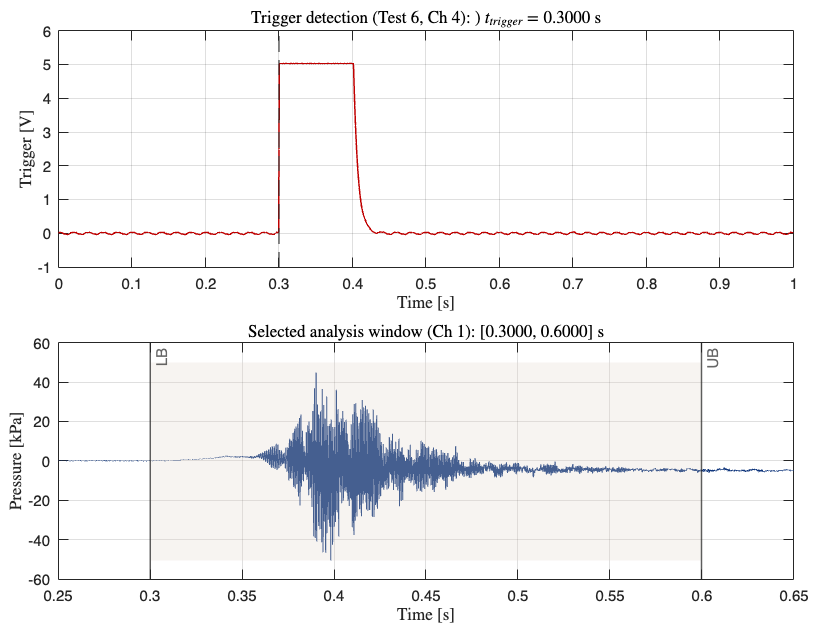

plotWindow = [max(0, LB_window - plotPad), UB_window + plotPad];
[t_pPlot, pPlot, ~] = AuxFcn_GetWindowedSignal_000( ...
    testSignalTensor, validNSamples, fsByTest, TestIdx, ChIdx, plotWindow, true);

figure;
tiledlayout(2,1,'TileSpacing','compact','Padding','compact');

% Trigger
nexttile;
plot(t_trig, y_trig_s, 'LineWidth', 1, 'Color',Red_Dark); hold on;
xline(t_trigger, '--', 'LineWidth', 1);
grid on; box on;
xlabel('Time [s]','Interpreter','latex');
ylabel('Trigger [V]','Interpreter','latex');
title(sprintf('Trigger detection (Test %d, Ch %d): ) $t_{trigger}=$%.4f s', ...
    TestIdx, triggerChIdx, t_trigger), 'Interpreter','latex');
hold off;

% Pressure + window
nexttile;
plot(t_pPlot, pPlot, 'LineWidth', 0.5, 'Color',LUBlue); hold on;
yl = ylim;

patch([LB_window UB_window UB_window LB_window], ...
    [yl(1) yl(1) yl(2) yl(2)], ...
    LUCopper_Light, 'EdgeColor','none', 'FaceAlpha',0.25);

xline(LB_window, '-', 'LB', 'LineWidth', 1);
xline(UB_window, '-', 'UB', 'LineWidth', 1);

grid on; box on;
xlabel('Time [s]','Interpreter','latex');
ylabel('Pressure [kPa]','Interpreter','latex');
title(sprintf('Selected analysis window (Ch %d): [%.4f, %.4f] s', ...
    ChIdx, LB_window, UB_window), 'Interpreter','latex');
hold off;

Step 1 — read trigger channel (volts) and precondition

% TestIdx = 6;                  % Test used for filter design
% triggerChIdx = 4;             % Channel 4 -> Y[3] trigger voltage
% triggerWindow = [0.0, 1.0];   % Window to search for trigger [s]
% 
% assert(TestIdx >= 1 && TestIdx <= nTests, 'TestIdx out of range.');
% assert(validNChannels(TestIdx) >= triggerChIdx, ...
%     'Selected test does not contain channel %d.', triggerChIdx);
% 
% [t_trig, y_trig, Fs_trig] = AuxFcn_GetWindowedSignal_000( ...
%     testSignalTensor, validNSamples, fsByTest, TestIdx, triggerChIdx, triggerWindow, false);
% 
% % Light smoothing to suppress high-frequency noise on trigger
% % (keep it mild so we don't smear timing)
% y_trig_s = movmean(y_trig, max(5, round(0.0005*Fs_trig)));  % ~0.5 ms window

Step 2 — detect trigger time (robust step detection)

% % Baseline stats from early part of trigger window
% t0_base = triggerWindow(1);
% t1_base = triggerWindow(1) + 0.05;          % first 50 ms as baseline
% idxBase = (t_trig >= t0_base) & (t_trig <= t1_base);
% assert(any(idxBase), 'Trigger baseline window contains no samples.');
% 
% mu0 = median(y_trig_s(idxBase));
% sig0 = 1.4826 * median(abs(y_trig_s(idxBase) - mu0));      % robust sigma (MAD)
% 
% % Threshold crossing with persistence (avoids noise hits)
% thr = mu0 + 5*sig0;
% nPersist = max(10, round(0.001*Fs_trig));   % must stay high for 1 ms
% 
% idxCross = find(y_trig_s > thr, 1, 'first');
% assert(~isempty(idxCross), 'No trigger crossing found. Check triggerChIdx or threshold.');
% 
% % enforce persistence
% idxTrig = [];
% for k = idxCross:(length(y_trig_s)-nPersist)
%     if all(y_trig_s(k:(k+nPersist-1)) > thr)
%         idxTrig = k;
%         break;
%     end
% end
% assert(~isempty(idxTrig), 'Trigger did not satisfy persistence condition.');
% 
% t_trigger = t_trig(idxTrig);
% 

Step 3 — define analysis window around trigger

% % Define analysis window relative to trigger
% preTime  = 0.02;   % 20 ms before trigger (baseline + early rise)
% postTime = 0.50;   % 500 ms after trigger (covers first peak + early dynamics)
% LB_window = max(0, t_trigger - preTime);
% UB_window = t_trigger + postTime;
% 
% ChIdx = 1;                       % pressure channel
% Window = [LB_window, UB_window]; % final analysis window [s]
% 

 Step 4 — extract pressure in that window

% assert(validNChannels(TestIdx) >= ChIdx, ...
%     'Selected test does not contain channel %d.', ChIdx);
% assert(Window(1) < Window(2), 'Window must satisfy [tStart < tEnd].');
% 
% [t_windowed, y_windowed, Fs] = AuxFcn_GetWindowedSignal_000( ...
%     testSignalTensor, validNSamples, fsByTest, TestIdx, ChIdx, Window, true);

### 3.2 EWT-Guided Cutoff Frequency Identification

#### 3.2.1 Signal Decomposition by MRA using Empirical Wavelet Transform (EWT) 

**Objective: **Obtain a data-adaptive multiresolution analysis (MRA) of the selected pressure signal (y_windowed) and extract the EWT filter-bank passbands [Li, Ui]. These passbands define a data-driven spectral partition used later to build candidate low-pass filter specifications.

**Workflow:**

- run EWT on selected windowed signal

- run EWT with MaxNumPeaks

- convert normalized peak/passband frequencies to Hz

- check reconstruction and energy preservation

- summarize modes in table and plot original + IMFs

- build sorted candidate cutoff list in practical range

**Notes on terminology: **Multiresolution analysis **(MRA), **Empirical Wavelet Transform **(EWT).**

assert(exist('ewt', 'file') == 2, ...
    'EWT function not available. Requires Wavelet Toolbox with ewt().');

MaxNumPeaks = 10;  % Maximum number of peaks retained in EWT segmentation (MATLAB ewt option)

% Ensure column vectors for consistent behavior
y_ewt = y_windowed(:);

% Run EWT
[mra, cfs, wfb, info] = ewt(y_ewt, 'MaxNumPeaks', MaxNumPeaks);

% Convert normalized peak frequencies and passbands to Hz
PeakFrequencies_Hz = Fs * info.PeakFrequencies(:);

Passbands_Hz = Fs * info.FilterBank.Passbands;   % rows correspond to MRA components
Passbands_Hz = sort(Passbands_Hz, 2);            % enforce [Li Ui] per row

Li = Passbands_Hz(:,1);
Ui = Passbands_Hz(:,2);


#### 3.2.2 Reconstruction and energy checks (sanity / traceability)

Signal reconstruction check (MRA components sum to original signal)

recon = sum(mra, 2);
SignalReconCheck = max(abs(y_ewt - recon));

% Coefficient energy preservation check (as used in MATLAB documentation)
signalEnergy = norm(y_ewt,2)^2;
cfsEnergy = sum(sum(abs(cfs).^2));
EnergyPreservRelDiffCheck = ((cfsEnergy - signalEnergy) / signalEnergy) * 100;

fprintf('EWT reconstruction max|err|: %.3e\n', SignalReconCheck);

EWT reconstruction max|err|: 2.842e-14


fprintf('EWT energy check (coeffs vs signal): rel diff = %.3f %%\n', EnergyPreservRelDiffCheck);

EWT energy check (coeffs vs signal): rel diff = 0.000 %


#### 3.2.3 Per-component metadata table (passbands + peaks-in-band + energy share)

numModes = size(mra,2);

% Energy fraction per component (useful for interpretation and later reporting)
modeEnergy = sum(abs(mra).^2, 1).';     % per component
modeEnergyPct = 100 * modeEnergy / sum(modeEnergy);

% Associate detected segmentation peaks to passbands (a band may contain multiple peaks)
peaksInBand = cell(numModes,1);
nPeaksInBand = zeros(numModes,1);

for j = 1:numModes
    inBand = (PeakFrequencies_Hz >= Li(j)) & (PeakFrequencies_Hz < Ui(j));
    peaksInBand{j} = PeakFrequencies_Hz(inBand);
    nPeaksInBand(j) = sum(inBand);
end

% A characteristic frequency for ordering/annotation (geometric mean of band edges)
bandCenter_Hz = sqrt(max(Li,eps).*max(Ui,eps));

EWT_SummaryTable = table( ...
    (1:numModes).', Li, Ui, bandCenter_Hz, modeEnergyPct, nPeaksInBand, peaksInBand, ...
    'VariableNames', {'EWT_MRA_Component','PassbandLow_Hz','PassbandHigh_Hz', ...
    'BandCenter_Hz','ModeEnergy_pct','NumPeaksInBand','PeaksInBand_Hz'} );

disp(EWT_SummaryTable);

    EWT_MRA_Component    PassbandLow_Hz    PassbandHigh_Hz    BandCenter_Hz    ModeEnergy_pct    NumPeaksInBand     PeaksInBand_Hz 
    _________________    ______________    _______________    _____________    ______________    ______________    ________________

            1                2613.3          1.0417e+05             16499          13.481              1           {[ 2.8300e+003]}
            2                2393.3              2613.3            2500.9          1.9139              1           {[ 2.4100e+003]}
            3                1756.7              2393.3            2050.4          4.6889              1           {[ 2.3767e+003]}
            4                  1270              1756.7            1493.6          5.3518            

#### 3.2.4 Plot: original signal + first N MRA components

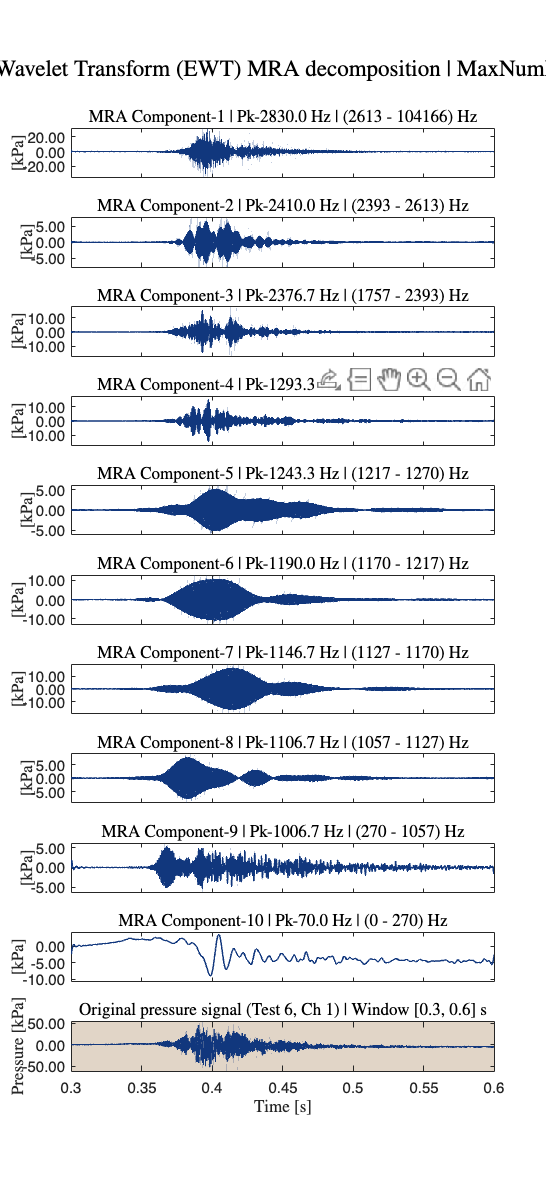

%% 3.2.4 Plot: EWT MRA components (MATLAB order) + original signal at bottom
% Requirements:
% - Respect MATLAB’s native MRA component ordering (no sorting by Li).
% - Show peak frequency in titles (if available) + passband limits.
% - Include units on vertical axes ([kPa]).
% - Apply background color styling to the original signal subplot.
% - Place the original signal at the bottom.
% - Y-axis label orientation controlled by yLabelRotationDeg (0 = horizontal, 90 = vertical).

% --- User control for y-label orientation ---
yLabelRotationDeg = 90;   % set 0 for horizontal, 90 for vertical, -90 to flip

% --- Use MATLAB order directly (no reordering) ---
mra_plot = mra;
Li_plot  = Li;
Ui_plot  = Ui;

numModes = size(mra_plot,2);
nPlotModes = min(numModes, MaxNumPeaks);

% Representative peak per component (optional but recommended)
% If you already computed repPeakHz earlier, it will be used. Otherwise compute:
if ~exist('repPeakHz','var')
    repPeakHz = nan(numModes,1);
    if exist('PeakFrequencies_Hz','var')
        for j = 1:numModes
            inBand = (PeakFrequencies_Hz >= Li_plot(j)) & (PeakFrequencies_Hz < Ui_plot(j));
            if any(inBand)
                repPeakHz(j) = PeakFrequencies_Hz(find(inBand,1,'first'));
            end
        end
    end
end

figure
x0=15; y0=15; width=100; height=20*(nPlotModes+1);
set(gcf,'units','centimeters','position',[x0,y0,width,height])

% --- Plot MRA components first (top) ---
for k = 1:nPlotModes
    modesAx = subplot(nPlotModes+1,1,k);
    plot(t_windowed, mra_plot(:,k), 'Color', LUBlue, 'LineWidth', 1);

    % Y-axis label + formatting
    ylabel('[kPa]', 'Interpreter','latex');
    ytickformat('%.2f')
    ax = gca;
    ax.YAxis.Exponent = 0;

    % Y-label orientation (controlled)
    modesAx.YLabel.Rotation = yLabelRotationDeg;
    if yLabelRotationDeg == 0
        modesAx.YLabel.HorizontalAlignment = 'right';
        modesAx.YLabel.VerticalAlignment = 'middle';
    else
        modesAx.YLabel.HorizontalAlignment = 'center';
        modesAx.YLabel.VerticalAlignment = 'middle';
    end

    % Limits with margin (same style as your original)
    ylimMax = max(mra_plot(:,k));
    ylimMin = min(mra_plot(:,k));
    ylim([ylimMin + ylimMin*0.2, ylimMax + ylimMax*0.2])

    % Title with peak + passband
    if ~isnan(repPeakHz(k))
        peakText = sprintf('Pk-%.1f Hz', repPeakHz(k));
    else
        peakText = 'Pk-NaN';
    end
    title(sprintf('MRA Component-%d | %s | (%.0f - %.0f) Hz', ...
        k, peakText, Li_plot(k), Ui_plot(k)), 'Interpreter','latex');

    grid off; box on;

    % Hide x tick labels except for the bottom-most subplot (original signal)
    set(gca,'xticklabel',[]);
end

% --- Plot original signal at bottom (with background color) ---
signalAx = subplot(nPlotModes+1,1,nPlotModes+1);
plot(t_windowed, y_ewt, 'Color', LUBlue, 'LineWidth', 1);

% Background color + formatting
signalAx.Color = LUCopper_Light;
ytickformat('%.2f')
ax = gca;
ax.YAxis.Exponent = 0;

% Y-label orientation (controlled)
ylabel('Pressure [kPa]','Interpreter','latex');
signalAx.YLabel.Rotation = yLabelRotationDeg;
if yLabelRotationDeg == 0
    signalAx.YLabel.HorizontalAlignment = 'right';
    signalAx.YLabel.VerticalAlignment = 'middle';
else
    signalAx.YLabel.HorizontalAlignment = 'center';
    signalAx.YLabel.VerticalAlignment = 'middle';
end

ylimMax = max(y_ewt);
ylimMin = min(y_ewt);
ylim([ylimMin + ylimMin*0.2, ylimMax + ylimMax*0.2])

xlabel('Time [s]','Interpreter','latex');
title(sprintf('Original pressure signal (Test %d, Ch %d) | Window [%.1f, %.1f] s', ...
    TestIdx, ChIdx, Window(1), Window(2)), 'Interpreter','latex');

grid off; box on;

sgtitle(sprintf('Empirical Wavelet Transform (EWT) MRA decomposition | MaxNumPeaks = %d', ...
    MaxNumPeaks), 'Interpreter','latex');

% ewtTestIdx = 6;          % Test used for EWT 
% ewtChIdx = 1;            % Channel 1 -> Y[0] pressure signal
% ewtWindow = [0.0, 3.0];  % Analysis time window [s]
% 
% MaxNumPeaks = 10;
% EWTresults = struct(); % Store results for each test
% summaryData = [];   % Initialize numerical data matrix
% i = 1;
% 
% assert(exist('ewt', 'file') == 2, ...
%     'EWT function not available. Requires Wavelet Toolbox with ewt().');
% assert(ewtTestIdx >= 1 && ewtTestIdx <= nTests, 'ewtTestIdx must be in [1, %d].', nTests);
% assert(validNChannels(ewtTestIdx) >= ewtChIdx, ...
%     'Selected test does not contain channel %d.', ewtChIdx);
% 
% % [t, dataP, Fs] = AuxFcn_GetWindowedSignal_000( ...
% %     testSignalTensor, validNSamples, fsByTest, ewtTestIdx, ewtChIdx, ewtWindow, true);
% % fprintf('Processing Test %d...\n', ewtTestIdx);
% 
% % Perform EWT on the selected test
% [mra_ewt, cfs, wfb, info] = ewt(y_windowed, 'MaxNumPeaks',MaxNumPeaks);
% % Convert peak frequencies and passbands to Hz
% PeakFrequencies = Fs * info.PeakFrequencies;
% freqPassbands = Fs * info.FilterBank.Passbands;
% 
% % Build per-mode frequency metadata (mode -> passband/peak) for robust ordering.
% numModes = size(mra_ewt,2);
% modePeakHz = nan(numModes,1);
% modeBandLowHz = nan(numModes,1);
% modeBandHighHz = nan(numModes,1);
% 
% if isfield(info,'FilterBank') && istable(info.FilterBank) && ...
%         ismember('MRAComponent', info.FilterBank.Properties.VariableNames)
%     mraComponentIdx = info.FilterBank.MRAComponent;
% else
%     mraComponentIdx = (1:size(freqPassbands,1)).';
% end
% 
% nMap = min(numel(mraComponentIdx), size(freqPassbands,1));
% for iMap = 1:nMap
%     modeIdxMap = mraComponentIdx(iMap);
%     if modeIdxMap >= 1 && modeIdxMap <= numModes
%         modeBandLowHz(modeIdxMap) = freqPassbands(iMap,1);
%         modeBandHighHz(modeIdxMap) = freqPassbands(iMap,2);
%     end
% end
% 
% nPeaks = numel(PeakFrequencies);
% nAssign = min(nPeaks, numModes);
% for iPeak = 1:nAssign
%     modePeakHz(iPeak) = PeakFrequencies(iPeak);
% end
% 
% modeOrderKey = modeBandLowHz;
% noBandIdx = isnan(modeOrderKey);
% modeOrderKey(noBandIdx) = modePeakHz(noBandIdx);
% modeOrderKey(isnan(modeOrderKey)) = inf;
% [~, modeOrderAscAll] = sort(modeOrderKey, 'ascend');
% 
% % Reindex components by ascending frequency:
% % Ordered component 1 = lowest-frequency mode, etc.
% mra_ewt_sorted = mra_ewt(:, modeOrderAscAll);
% modePeakHz_sorted = modePeakHz(modeOrderAscAll);
% modeBandLowHz_sorted = modeBandLowHz(modeOrderAscAll);
% modeBandHighHz_sorted = modeBandHighHz(modeOrderAscAll);
% 
% % Store results for each test
% EWTresults(i).TestNumber = ewtTestIdx;
% EWTresults(i).MRA = mra_ewt;
% EWTresults(i).Coefficients = cfs;
% EWTresults(i).WaveletBank = wfb;
% EWTresults(i).PeakFrequencies = PeakFrequencies;
% EWTresults(i).Passbands = freqPassbands;
% 
% %% Signal Reconstruction
% % Logical array for selecting reconstruction elements
% levelForReconstruction = false(1, size(mra_ewt,2));
% levelForReconstruction(end) = true;
% % Sum down the rows of the selected multiresolution signals
% EWTresults(i).SignalRecon = sum(mra_ewt(:,levelForReconstruction),2);
% 
% %% Signal Reconstruction Verification
% % Verify that summing the MRA components results in perfect reconstruction of the signal.
% EWTresults(i).SignalReconCheck = max(abs(dataP - sum(mra_ewt,2)));
% 
% % Verify energy preservation of the EWT analysis coefficients.
% signalEnergy = norm(dataP,2)^2;
% cfsenergy = sum(sum(abs(cfs).^2));
% EWTresults(i).Energy= [signalEnergy cfsenergy];
% EWTresults(i).EnergyPreservRelDiffCheck= ((cfsenergy- signalEnergy)/signalEnergy) * 100;% [%]
% 
% % Append numerical data for structured table
% for j = 1:numModes
%     peakHz = modePeakHz_sorted(j);
%     bandLow = modeBandLowHz_sorted(j);
%     bandHigh = modeBandHighHz_sorted(j);
%     % summaryData = [summaryData; ewtTestIdx, ewtChIdx, j, modeOrderAscAll(j), peakHz, bandLow, bandHigh];
%     summaryData = [summaryData; ewtTestIdx, ewtChIdx, j, peakHz, bandLow, bandHigh];
% end
% 
% % Structured summary table for report/readability.
% % ewtSummaryTable = array2table(summaryData, ...
% %     'VariableNames', {'TestNumber','ChannelNumber','EWT_MRA_Component','OriginalMRAIndex','PeakFrequency_Hz','PassbandLow_Hz','PassbandHigh_Hz'});
% ewtSummaryTable = array2table(summaryData, ...
%     'VariableNames', {'TestNumber','ChannelNumber','EWT_MRA_Component','PeakFrequency_Hz','PassbandLow_Hz','PassbandHigh_Hz'});
% disp(ewtSummaryTable);
% 
% nPlotModes = min(MaxNumPeaks, size(mra_ewt,2));
% 
% figure
%     x0=10;
%     y0=10;
%     width = 75;
%     height = 15 * nPlotModes;
%     set(gcf,'units','centimeters','position',[x0,y0,width,height])
%     signal = subplot(nPlotModes+1,1,1);
%     plot(t,dataP,'Color',LUBlue);
%     ytickformat('%.2f')
%     ax = gca;
%     ax.YAxis.Exponent = 0;  % Disables scientific notation
%     ylimMax = max(dataP);
%     ylimMin = min(dataP);
%     ylim([ylimMin + ylimMin * 0.2  ylimMax + ylimMax * 0.2 ])
%     signal.Color = LUCopper_Light;
%     signal.YLabel.Rotation = 0;
%     signal.YLabel.HorizontalAlignment = 'right';
%     signal.YLabel.VerticalAlignment = 'middle';
%     title(sprintf('Original Signal (Window %.3f-%.3f s)', ewtWindow(1), ewtWindow(2)),'Interpreter','latex')
%     sgtitle(['Empirical Wavelet Transform - Test - ',num2str(ewtTestIdx), ...
%         sprintf(' | Window %.3f-%.3f s', ewtWindow(1), ewtWindow(2))],'Interpreter','latex')
%     ylabel('Pressure [kPa]','Interpreter','latex')
%     axis tight
%     set(gca,'xticklabel',[])
%     for k=1:nPlotModes
%         modes = subplot(nPlotModes+1,1,k+1);
%         plot(t,mra_ewt_sorted(:,k),'Color',LUBlue)
%         ylabel(['EWT MRA component - ',num2str(k), ' [kPa]'],'Interpreter','latex')
%         ytickformat('%.2f')
%         ax = gca;
%         ax.YAxis.Exponent = 0;  % Disables scientific notation
%         ylimMax = max(mra_ewt_sorted(:,k));
%         ylimMin = min(mra_ewt_sorted(:,k));
%         ylim([ylimMin + ylimMin * 0.2  ylimMax + ylimMax * 0.2 ])
%         modes.YLabel.Rotation = 0;
%         modes.YLabel.HorizontalAlignment = 'right';
%         modes.YLabel.VerticalAlignment = 'middle';
%         if ~isnan(modePeakHz_sorted(k))
%             peakText = num2str(modePeakHz_sorted(k), '%.1f');
%         else
%             peakText = 'NaN';
%         end
%         if ~isnan(modeBandLowHz_sorted(k)) && ~isnan(modeBandHighHz_sorted(k))
%             title(['EWT MRA component-' num2str(k) ' Pk-' peakText '[Hz]' ' - ' ' (' num2str(modeBandLowHz_sorted(k), '%.0f') ' - ' num2str(modeBandHighHz_sorted(k), '%.0f') ') [Hz]'],'Interpreter','latex')
%         else
%             title(['EWT MRA component-' num2str(k) ' Pk-' peakText '[Hz]'],'Interpreter','latex')
%         end
%         axis tight
%         if k < nPlotModes
%             set(gca,'xticklabel',[])
%         else
%             xlabel('Time [s]')
%         end
%     end

% MaxNumPeaks = 10; % Set max number of spectral peaks for EWT segmentation
% [mra, cfs, wfb, info] = ewt(y_windowed, 'MaxNumPeaks', MaxNumPeaks);
% 
% % --- Convert normalized passband limits to Hz (using Fs, as you already do) ---
% Passbands_Hz = Fs * info.FilterBank.Passbands;   % [Li Ui] in Hz (rows)
% Passbands_Hz = sort(Passbands_Hz, 2);            % enforce Li < Ui per row
% 
% Li = Passbands_Hz(:,1);                          % lower passband edges (Hz)
% Ui = Passbands_Hz(:,2);                          % upper passband edges (Hz)
% 
% % --- Extract peaks from info structure ---
% peakFreq_Hz = Fs * info.PeakFrequencies;                  % convert to Hz using Fs
% 
% % --- Number of components and peaks ---
% numBands = size(Passbands_Hz, 1);
% numPeaks = length(peakFreq_Hz);
% 
% % --- Build summary table ---
% if numPeaks == numBands
%     % Simple one-to-one correspondence: each peak corresponds to a band
%     summaryTable = table( (1:numBands)', peakFreq_Hz, Li, Ui, ...
%                           'VariableNames', {'Component', 'Peak_Hz', 'Low_Hz', 'High_Hz'});
% else
%     % If numbers differ, match each peak to the band that contains it
%     compIdx = zeros(numPeaks, 1);
%     assignedLow = zeros(numPeaks, 1);
%     assignedHigh = zeros(numPeaks, 1);
%     validPeak = false(numPeaks, 1);
% 
%     for i = 1:numPeaks
%         f = peakFreq_Hz(i);
%         % Find band where Li <= f < Ui (assuming bands are contiguous and cover [0, Fs/2])
%         inBand = (f >= Li) & (f < Ui);
%         if any(inBand)
%             compIdx(i) = find(inBand, 1);
%             assignedLow(i) = Li(compIdx(i));
%             assignedHigh(i) = Ui(compIdx(i));
%             validPeak(i) = true;
%         end
%     end
% 
%     % Keep only peaks that fall inside a band
%     summaryTable = table( compIdx(validPeak), peakFreq_Hz(validPeak), ...
%                           peakMag(validPeak), assignedLow(validPeak), assignedHigh(validPeak), ...
%                           'VariableNames', {'EWT MRA component', 'Peak_Hz', 'Peak_Magnitude', 'Low_Hz', 'High_Hz'});
% 
%     % Optionally list bands without a peak
%     bandsWithPeaks = unique(compIdx(validPeak));
%     bandsWithoutPeak = setdiff(1:numBands, bandsWithPeaks);
%     if ~isempty(bandsWithoutPeak)
%         fprintf('Bands without an associated peak: %s\n', mat2str(bandsWithoutPeak));
%     end
% end
% 
% % --- Display the table ---
% disp(summaryTable);
% 
% % --- (Optional) Save table to file ---
% % writetable(summaryTable, 'EWT_components.csv');


#### 3.2.2 Candidate Cutoff Frequency Selection

**Rationale:** The EWT segmentation provides local band limits [Li, Ui] for each extracted component. To avoid placing a physically relevant spectral component at the Butterworth half-power point (−3 dB), we define candidate passband edges fp,i above the upper EWT boundary Ui using a bandwidth-proportional margin. The stopband edge fs,i is then placed one additional local band width above fp,i.

**Definitions:**

- Local EWT band width:    Bi = Ui - Li

- Passband edge (cutoff):  fp,i = Ui + gamma * Bi

- Stopband edge:           fs,i = fp,i + kWidth * Bi

**Robustness constraints:** Impose a minimum transition width (absolute + relative) and enforce fs < Nyquist to prevent ill-conditioned designs (Ws ≈ Wp) and numerical pathologies.

% --- user-defined parameters (explicit) ---
gamma           = 1.0;   % bandwidth-proportional margin above Ui (dimensionless)
kWidth          = 1.0;   % additional band-width from fp to fs (dimensionless)
minDeltaAbsHz   = 10;    % absolute lower bound for (fs - fp) [Hz]
minDeltaRelFrac = 0.02;  % relative lower bound for (fs - fp) as fraction of fp [-]
minCutHz        = 1;     % discard candidates below this fp (set 20 if desired) [Hz]
% ------------------------------------------

nyq = Fs/2;

% Local EWT bandwidth
Bi = Ui - Li;

% Candidate passband edge (Hz): push above the EWT upper boundary
cutoff_frequencies = Ui + gamma.*Bi;                 % fp

% Candidate stopband edge (Hz): one additional local bandwidth above fp
stop_frequencies   = cutoff_frequencies + kWidth.*Bi;% fs (initial)

% Enforce minimum transition width: max(absolute, relative)
deltaMin = max(minDeltaAbsHz, minDeltaRelFrac.*cutoff_frequencies);
stop_frequencies = max(stop_frequencies, cutoff_frequencies + deltaMin);

% Enforce Nyquist constraint
stop_frequencies = min(stop_frequencies, nyq - 1);

% Practical validity filtering
valid = isfinite(cutoff_frequencies) & isfinite(stop_frequencies) & ...
        cutoff_frequencies >= minCutHz & ...
        cutoff_frequencies < 0.98*nyq & ...
        stop_frequencies > cutoff_frequencies;

cutoff_frequencies = cutoff_frequencies(valid);
stop_frequencies   = stop_frequencies(valid);

% Sort candidates for downstream sensitivity sweeps
[cutoff_frequencies, idx] = sort(cutoff_frequencies, 'ascend');
stop_frequencies = stop_frequencies(idx);

assert(~isempty(cutoff_frequencies), ...
    'No valid EWT-derived cutoff/stopband pairs after range filtering.');

% Diagnostic output (recommended during development)
deltaHz = stop_frequencies - cutoff_frequencies;
disp(table(cutoff_frequencies, stop_frequencies, deltaHz, ...
    'VariableNames', {'fp_Hz','fs_Hz','Delta_Hz'}));

### 3.3 Low-Pass Filter Sensitivity Analysis

#### 3.3.1 Filter-Order and Cutoff Sweep

**Objective: **Quantify sensitivity of integral and peak metrics (signal energy, impulse, peak pressure) to the low-pass specification across EWT-derived candidates and a range of filter orders.

**Workflow:**

-  preliminary filter deisgn. compute minimum Butterworth order for each candidate cutoff

- evaluate a range of filter orders

- compute metric ratios vs unfiltered signal

- select final cutoff using robustness criteria

**Filter Order Design Parameters**

n = zeros(size(cutoff_frequencies,1),1);
for i = 1:length(cutoff_frequencies)
    fc = cutoff_frequencies(i);       % Passband edge candidate (Hz)
    fs_stop = stop_frequencies(i);    % Stopband edge candidate (Hz)
    Rp = 3;                           % Passband attenuation at Wp (dB)
    Rs = 40;                          % Stopband attenuation at Ws (dB)

    Wp = fc / (Fs/2);
    Ws = fs_stop / (Fs/2);

    n(i) = buttord(Wp, Ws, Rp, Rs);
end

nMin = max(n);
filter_orders = [nMin, nMin + 2, nMin + 4, nMin + 6]

**Performance Metrics**

energy_ratio_matrix = zeros(length(filter_orders), length(cutoff_frequencies));
impulse_ratio_matrix = zeros(length(filter_orders), length(cutoff_frequencies));
peak_pressure_ratio_matrix = zeros(length(filter_orders), length(cutoff_frequencies));

E_base = sum(abs(y_windowed).^2);
Impulse_base = trapz(t_windowed, y_windowed);
PeakPressure_base = max(y_windowed);

%% Filtering + Metrics (correctly enforces Wp/Ws/Rp/Rs; uses SOS for stability)
for f_idx = 1:length(filter_orders)
    filter_order = filter_orders(f_idx);

    for c_idx = 1:length(cutoff_frequencies)
        fc = cutoff_frequencies(c_idx);
        fs_stop = stop_frequencies(c_idx);

        Rp = 3;
        Rs = 40;

        Wp = fc / (Fs/2);
        Ws = fs_stop / (Fs/2);

        % --- Determine a Butterworth cutoff (Wn_current) that satisfies both constraints ---
        % Butterworth magnitude model:
        %   |H(jw)|^2 = 1/(1 + (w/Wn)^(2n))
        % Passband constraint at Wp:  Ap=Rp => (Wp/Wn)^(2n) <= (10^(Rp/10)-1)
        % Stopband constraint at Ws:  As=Rs => (Ws/Wn)^(2n) >= (10^(Rs/10)-1)
        %
        % This yields a feasible interval for Wn:
        %   Wn >= Wp / (10^(Rp/10)-1)^(1/(2n))    (passband lower bound)
        %   Wn <= Ws / (10^(Rs/10)-1)^(1/(2n))    (stopband upper bound)
        %
        % We choose the largest feasible Wn (most conservative wrt preserving passband content),
        % i.e. Wn_current = Wn_stop, provided feasibility holds.

        Ap = 10^(Rp/10) - 1;
        As = 10^(Rs/10) - 1;

        Wn_pass = Wp / (Ap)^(1/(2*filter_order));   % minimum Wn to satisfy passband
        Wn_stop = Ws / (As)^(1/(2*filter_order));   % maximum Wn to satisfy stopband

        % Feasibility check (should hold for filter_order >= nMin)
        if Wn_pass > Wn_stop
            % If this triggers, the selected order cannot satisfy both specs for this candidate.
            % Keep the design conservative w.r.t. passband (use Wn_pass), but note that Rs will not be met.
            Wn_current = Wn_pass;
        else
            % Largest feasible cutoff -> least distortion in the retained band
            Wn_current = Wn_stop;
        end

        % Numerical safety: clamp to valid digital range
        Wn_current = min(max(Wn_current, eps), 0.999999);

        % --- Design + apply in SOS form ---
        [z,p,k] = butter(filter_order, Wn_current, 'low');
        [sos,g] = zp2sos(z,p,k);

        % Apply zero-phase filtering (compatibility across MATLAB versions/toolboxes)
        try
            % Some MATLAB versions support SOS directly via filtfilt
            p_filtered = filtfilt(sos, g, y_windowed);
        catch
            % Fallback: convert ZPK -> (b,a) and use standard filtfilt
            [b,a] = zp2tf(z,p,k);
            p_filtered = filtfilt(b, a, y_windowed);
        end

        % --- Metrics ---
        E_filtered = sum(abs(p_filtered).^2);
        Impulse_filtered = trapz(t_windowed, p_filtered);
        PeakPressure_filtered = max(p_filtered);

        energy_ratio_matrix(f_idx, c_idx) = (E_filtered / E_base) * 100;
        impulse_ratio_matrix(f_idx, c_idx) = (Impulse_filtered / Impulse_base) * 100;
        peak_pressure_ratio_matrix(f_idx, c_idx) = (PeakPressure_filtered / PeakPressure_base) * 100;
    end
end

**Performance Metrics**

energy_ratio_matrix = zeros(length(filter_orders), length(cutoff_frequencies));
impulse_ratio_matrix = zeros(length(filter_orders), length(cutoff_frequencies));
peak_pressure_ratio_matrix = zeros(length(filter_orders), length(cutoff_frequencies));

E_base = sum(abs(y_windowed).^2);
Impulse_base = trapz(t_windowed, y_windowed);
PeakPressure_base = max(y_windowed);

for f_idx = 1:length(filter_orders)
    for c_idx = 1:length(cutoff_frequencies)
        fc = cutoff_frequencies(c_idx);
        filter_order = filter_orders(f_idx);
        lpFilt = designfilt('lowpassiir', ...
            'FilterOrder', filter_order, ...
            'HalfPowerFrequency', fc, ...
            'DesignMethod','butter', ...
            'SampleRate', Fs);

        p_filtered = filtfilt(lpFilt, y_windowed);
        E_filtered = sum(abs(p_filtered).^2);
        Impulse_filtered = trapz(t_windowed, p_filtered);
        PeakPressure_filtered = max(p_filtered);

        energy_ratio_matrix(f_idx, c_idx) = (E_filtered / E_base) * 100;
        impulse_ratio_matrix(f_idx, c_idx) = (Impulse_filtered / Impulse_base) * 100;
        peak_pressure_ratio_matrix(f_idx, c_idx) = (PeakPressure_filtered / PeakPressure_base) * 100;
    end
end

**Final cutoff selection rule**

smallest cutoff where all tested orders preserve >=98% impulse and peak.

% Final cutoff selection rule:
% smallest cutoff where all tested orders preserve >=98% impulse and peak.
meetsCriterion = all(impulse_ratio_matrix >= 98, 1) & all(peak_pressure_ratio_matrix >= 98, 1);
if any(meetsCriterion)
    lfCut = cutoff_frequencies(find(meetsCriterion, 1, 'first'));
else
    [~, idxBest] = max(mean(impulse_ratio_matrix + peak_pressure_ratio_matrix, 1));
    lfCut = cutoff_frequencies(idxBest);
end

#### 3.3.2 Summary Table (recommended for traceability)

deltaHz = stop_frequencies - cutoff_frequencies;
% Worst-case (most conservative) preservation across tested orders
min_energy_ratio = min(energy_ratio_matrix, [], 1).';
min_impulse_ratio = min(impulse_ratio_matrix, [], 1).';
min_peak_pressure_ratio = min(peak_pressure_ratio_matrix, [], 1).';

% Optional: average preservation across tested orders (less conservative)
mean_energy_ratio = mean(energy_ratio_matrix, 1).';
mean_impulse_ratio = mean(impulse_ratio_matrix, 1).';
mean_peak_pressure_ratio = mean(peak_pressure_ratio_matrix, 1).';

% Pass/fail per your rule (should match meetsCriterion)
meetsCriterion_col = meetsCriterion(:);

% Mark the selected cutoff
isSelected = cutoff_frequencies == lfCut;

summaryTable_3p3 = table( ...
    cutoff_frequencies(:), stop_frequencies(:), deltaHz(:), ...
    min_impulse_ratio, min_peak_pressure_ratio, min_energy_ratio, ...
    mean_impulse_ratio, mean_peak_pressure_ratio, mean_energy_ratio, ...
    meetsCriterion_col, isSelected(:), ...
    'VariableNames', { ...
        'fp_Hz','fs_Hz','Delta_Hz', ...
        'MinImpulse_pct','MinPeak_pct','MinEnergy_pct', ...
        'MeanImpulse_pct','MeanPeak_pct','MeanEnergy_pct', ...
        'MeetsCriterion','Selected' ...
    } );

disp(summaryTable_3p3);

% Optional: save for reporting/reproducibility
% writetable(summaryTable_3p3, sprintf('SummaryTable_3p3_Test%d.csv', TestIdx));


#### 3.3.3 Sensitivity Plots

figure;
tiledlayout(2,4, 'TileSpacing', 'compact', 'Padding', 'compact');

for f_idx = 1:length(filter_orders)
    nexttile(f_idx);
    plot(cutoff_frequencies, impulse_ratio_matrix(f_idx, :), '-s', ...
        'Color',LUBlue,'MarkerFaceColor',LUBlue_Light,'MarkerEdgeColor',LUBlue, 'LineWidth', 1);
    xlabel('Cutoff Frequency [Hz]', 'Interpreter', 'latex');
    xlim([-50 1050]);
    ylabel('Ratio [\%]', 'Interpreter', 'latex');
    ylim([min(min(impulse_ratio_matrix(:, :))) * 0.98, max(max(impulse_ratio_matrix(:, :))) * 1.02]);
    title({'Impulse Ratio',['(Filter Order = ' num2str(filter_orders(f_idx)) ')']},'Interpreter', 'latex');
    legend('Impulse Ratio', 'Location', 'northeast', 'Interpreter', 'latex');
    grid on;

    nexttile(f_idx + 4);
    plot(cutoff_frequencies, energy_ratio_matrix(f_idx, :), '-s', ...
        'Color',LUBlue,'MarkerFaceColor',LUBlue,'MarkerEdgeColor',LUBlue_Light, 'LineWidth', 1); hold on;
    plot(cutoff_frequencies, peak_pressure_ratio_matrix(f_idx, :), '-^', ...
        'Color',LUCopper,'MarkerEdgeColor',LUCopper,'MarkerFaceColor',LUCopper_Light, 'LineWidth', 1);
    hold off;
    xlabel('Cutoff Frequency [Hz]', 'Interpreter', 'latex');
    xlim([-50 1050]);
    ylabel('Ratio [\%]', 'Interpreter', 'latex');
    ylim([min(min([peak_pressure_ratio_matrix(:, :);energy_ratio_matrix(:, :)])) * 0.98, ...
          max(max([peak_pressure_ratio_matrix(:, :);energy_ratio_matrix(:, :)])) * 1.02]);
    title({'Signal Energy \& Peak Pressure Ratio vs. Cutoff',[' (Filter Order = ', num2str(filter_orders(f_idx)), ')']},'Interpreter', 'latex');
    legend('Signal Energy Ratio', 'Peak Pressure Ratio','Location', 'southeast', 'Interpreter', 'latex');
    grid on;
end
sgtitle({'\textbf{Low-Pass Filter Sensitivity Analysis}', ...
    sprintf('Test - %d | Selected cutoff %.1f Hz', TestIdx, lfCut)}, 'fontsize',14, 'Interpreter', 'latex')
hold off;


### 3.4 Final Filter Design and Phase Delay Effect

#### 3.4.1 Butterworth Filter at Selected Cutoff

**Objective: **design final low-pass filter using the selected EWT-guided cutoff and evaluate phase delay compensation in time domain.

fc = lfCut;
fs_stop = fc + 500;
Rp = 3;
Rs = 40;
Wp = fc / (Fs/2);
Ws = fs_stop / (Fs/2);
[filter_order, Wn] = buttord(Wp, Ws, Rp, Rs);

lpFilt = designfilt('lowpassiir', ...
    'FilterOrder', filter_order, ...
    'HalfPowerFrequency', lfCut, ...
    'DesignMethod','butter',...
    'SampleRate', Fs);

dataLowPass = filtfilt(lpFilt, y_windowed);
dataLowPassPhaseDelay = filter(lpFilt,y_windowed);


#### 3.4.2 Phase Delay Effect Plot

figure;
scatter(t_windowed, y_windowed, '.', ...
    'MarkerEdgeColor', LUCopper_Light, ...
    'MarkerEdgeAlpha', 1);
hold on;

plot(t_windowed, dataLowPassPhaseDelay, 'LineWidth', 1.5, 'Color', Red_Dark);
plot(t_windowed, dataLowPass, 'LineWidth', 1.5, 'Color', LUBlue);

title({"Compensate for the Delay Introduced by an IIR Filter", ...
       sprintf("Low-Pass Filtered at %.1f Hz", lfCut)}, 'fontsize', 16,'Interpreter','latex');
xlabel('Time [s]','Interpreter','latex');
ylabel('Pressure [kPa]','Interpreter','latex');
legend(sprintf('Test - %d: Original Signal (DC-Offset-Corrected)', TestIdx), ...
       sprintf("Phase Delay Not-Compensated Low-Pass Filtered at %.1f Hz", lfCut),...
       sprintf("Phase Delay Compensated Low-Pass Filtered at %.1f Hz", lfCut),...
       'Location','southeast', 'FontSize', 12,'Interpreter','latex');
box on;

zoom_start = 0.15;
zoom_end = 0.20;
zoom_idx = (t_windowed >= zoom_start) & (t_windowed <= zoom_end);

axes('Position', [0.55, 0.625, 0.35, 0.25]);
hold on;
scatter(t_windowed(zoom_idx), y_windowed(zoom_idx), '.', 'MarkerEdgeColor', LUCopper_Light);
plot(t_windowed(zoom_idx), dataLowPassPhaseDelay(zoom_idx), 'LineWidth', 1.5, 'Color', Red_Dark);
plot(t_windowed(zoom_idx), dataLowPass(zoom_idx), 'LineWidth', 1.5, 'Color', LUBlue);
xlabel('Time [s]','Interpreter','latex');
xlim([0.15 0.20]);
ylabel('Pressure [kPa]','Interpreter','latex');
box on;
hold off;

## 4. Quantity of Interest (QoI) Extraction of **∆Pmax [kPa] after Filtering**

### 4.1 Define CutOff Frequencies & Minimum Filter Order

cutoff_frequencies = 250:50:1000;
nMin = zeros(size(cutoff_frequencies,1),1);
for i = 1:length(cutoff_frequencies)
    % Given parameters
    fc = cutoff_frequencies(i);   % Passband cutoff frequency (Hz)
    fs_stop = cutoff_frequencies(i) + 500; % Stopband frequency (Hz)
    Rp = 3;      % Maximum ripple in passband (dB)
    Rs = 40;     % Minimum stopband attenuation (dB)

    % Normalize frequencies to Nyquist frequency (Fs/2)
    Wp = fc / (Fs/2);
    Ws = fs_stop / (Fs/2);

    % Compute minimum Butterworth filter order
    nMin(i) = buttord(Wp, Ws, Rp, Rs);
end
filter_orders = nMin;  % Filter orders

### 4.2 Calculation **∆Pmax [kPa] after Filtering**

% Memory Allocation
peakPressureFiltered = zeros(length(cutoff_frequencies), length(testNum));
%% Apply Low-Pass Filtering for Different Cutoff Frequencies & Filter Orders
for t_idx = 1:length(testNum)
    for fc_idx = 1:length(cutoff_frequencies)
        fc = cutoff_frequencies(fc_idx);  % Current cutoff frequency
        filter_order = filter_orders(fc_idx);  % Current filter order
        lpFilt = designfilt('lowpassiir', ...
        'FilterOrder', filter_order, ...
        'HalfPowerFrequency', fc, ...
         'DesignMethod','butter',...
        'SampleRate', Fs);
        % Zero-phase filtering
        pressureFiltered = filtfilt(lpFilt, dataP(:,t_idx));
        
        % Compute Peak pressure after filtering
        [peakPressureFiltered(fc_idx, t_idx), idx] = max(pressureFiltered, [], 1); % [kPa]
    end
end
DeltaP_max = max(peakPressureFiltered);

### 4.3 Plot **∆Pmax [kPa] after Filtering**

figure;
subplot(2,1,1)
boxplot(peakPressureFiltered, 'Whisker', Inf, 'Widths',.75);
h = findobj(gca,'Tag','Box');
for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),LUBlue_Light,'FaceAlpha',.25);
end

xlabel('Test Number','Interpreter','latex','FontSize',12)
ylabel ('$\Delta P_{Max}$ [kPa]','Interpreter','latex','FontSize',12)
title({'$\Delta P_{Max}$ Dispersion','Due to Different Low-Pass Filter $f_{c}$ Frequencies (250-1000 [Hz])'},'Interpreter','latex','FontSize',12)
box on
subplot(2,1,2)
scatter(dataRMH, DeltaP_max, 's','MarkerFaceColor',LUBlue); % Overlay mean values
hold on
ylabel ('$\Delta P_{Max}$ [kPa]','Interpreter','latex','FontSize',12)
xlabel('Released Mass of Hydrogen [g]','FontSize',12)
xlim([0 16])
ylim([-1 16])
grid on
box on
hold off

## Note on Multiresolution analysis **(MRA) **Empirical Wavelet Transform **(EWT).**

#### General Considerations

**1. Deflagration Pressure Signals Have Dominant Low-Frequency Components**

- The **overpressure rise** in deflagration events is often **gradual** compared to high-frequency noise.

- The **dominant physical processes** (combustion expansion, flame acceleration, venting effects) evolve on timescales much longer than **sensor vibrations or electronic noise**.

**2. Common Sources of High-Frequency Noise**

- **Sensor Vibrations & Structural Resonances:**

- Pressure transducers, particularly those mounted on rigid test chambers, can pick up **high-frequency mechanical vibrations**.

- **Electrical Noise:**

- Data acquisition (DAQ) systems and amplification circuits introduce **high-frequency interference**.

- **Shock-Induced Transients (if present):**

- If a strong shock develops, it may introduce **high-frequency components**, but **for deflagrations**, most of the pressure signal energy is **low-frequency**.

**3. Why a Low-Pass Filter is Appropriate?**

- The primarily interested in: 

- **Peak overpressure** **∆Pmax**

- **Impulse (integral of pressure over time)**

- **Time of peak pressure, **not as relevant as ∆Pmax, however, it is still considered a good metric to consider in the evaluation of the Low-Pass FIlter Effect during the Data Processing Procedure.

- These **key metrics** are **not affected by removing high-frequency noise**.

- A properly chosen **low-pass cutoff frequency** ensures the removal unwanted noise while **preserving** the physically meaningful pressure rise.

**4. Consideration for Cutoff Frequency Selection**

This is a challenge aspec of th edata processing due to the lack of knlodges about the frequencies a that migh tdominate the phenomena, however, several assumption required to be made.

- The **filter cutoff frequency** should be: 

- **Well above** the dominant deflagration pressure rise rate.

- **Below** the typical noise frequency components.

- A **frequency-domain analysis** (FFT or EWT) of the raw pressure signal) help to **identify the frequencies present in each test and determine** an **appropriate cutoff frequency.**

**Remark**

**Applying a low-pass filter makes sense** for the deflagration experiments **as long as the cutoff frequency is chosen appropriately**. 

To ensures that it is captured the **pressure response** while removing high-frequency noise that does not represent physical pressure changes.

#### Empirical Wavelet Transform (EWT) [3]

**Extracted from Matlab**

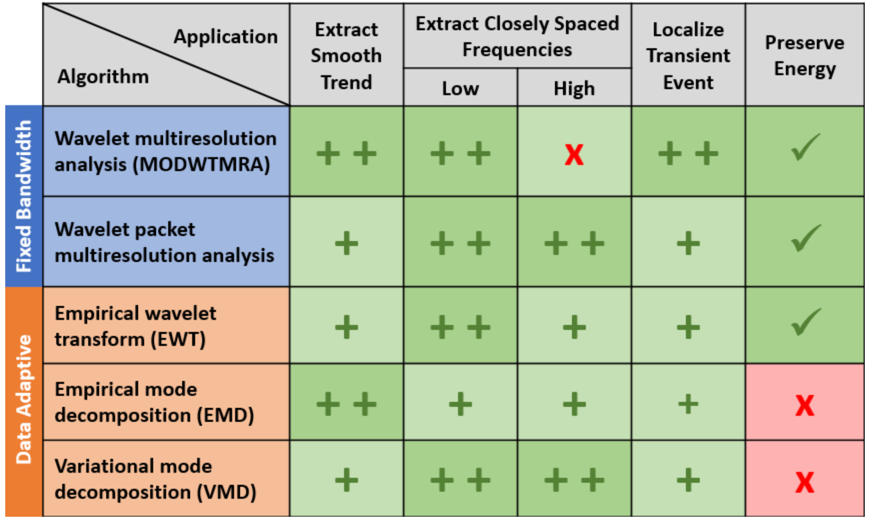

The key thing to note is that similar to the wavelet and EMD decompositions, VMD segregates the three components of interest into completely separate modes or into a small number of adjacent modes. All three techniques allow you to visualize signal components on the same time scale as the original signal. There is a data-adaptive technique which actually constructs wavelet filters based on the frequency content of the data. This technique is the *empirical wavelet transform *(EWT) [3]. One of the major criticisms of EMD is that its definition is purely algorithmic. As a result, it is not readily amenable to mathematical analysis. EWT on the other hand actually constructs Meyer wavelets based on the frequency content of the analyzed signal. Accordingly, the results of EWT are amenable to mathematical analysis because the filters used in the analysis are available to the user. Repeat the analysis of the synthetic signal using the EWT.

**References**

[1] Dragomiretskiy, Konstantin, and Dominique Zosso. “Variational Mode Decomposition.” *IEEE Transactions on Signal Processing* 62, no. 3 (February 2014): 531–44. [https://doi.org/10.1109/TSP.2013.2288675](https://doi.org/10.1109/TSP.2013.2288675).

[2] Flandrin, P., G. Rilling, and P. Goncalves. “Empirical Mode Decomposition as a Filter Bank.” *IEEE Signal Processing Letters* 11, no. 2 (February 2004): 112–14. [https://doi.org/10.1109/LSP.2003.821662](https://doi.org/10.1109/LSP.2003.821662).

[3] Giles, J. "Empirical wavelet transform", *IEEE Transactions on Signal Processing, *vol. 61, no. 16 (May 2013): 3999 - 4010. 

[4] Huang, Norden E., Zheng Shen, Steven R. Long, Manli C. Wu, Hsing H. Shih, Quanan Zheng, Nai-Chyuan Yen, Chi Chao Tung, and Henry H. Liu. “The Empirical Mode Decomposition and the Hilbert Spectrum for Nonlinear and Non-Stationary Time Series Analysis.” *Proceedings of the Royal Society of London. Series A: Mathematical, Physical and Engineering Sciences* 454, no. 1971 (March 8, 1998): 903–95. [https://doi.org/10.1098/rspa.1998.0193](https://doi.org/10.1098/rspa.1998.0193).

[5] Percival, Donald B., and Andrew T. Walden. *Wavelet Methods for Time Series Analysis*. Cambridge Series in Statistical and Probabilistic Mathematics. Cambridge ; New York: Cambridge University Press, 2000.

*Copyright 2019 The MathWorks, Inc.*